# FNN CNN LSTM - Basic Test

시간별 입력을 이해하는 것이 중요하다.

Here input `x` and targets `t` define a simple function that you can plot:

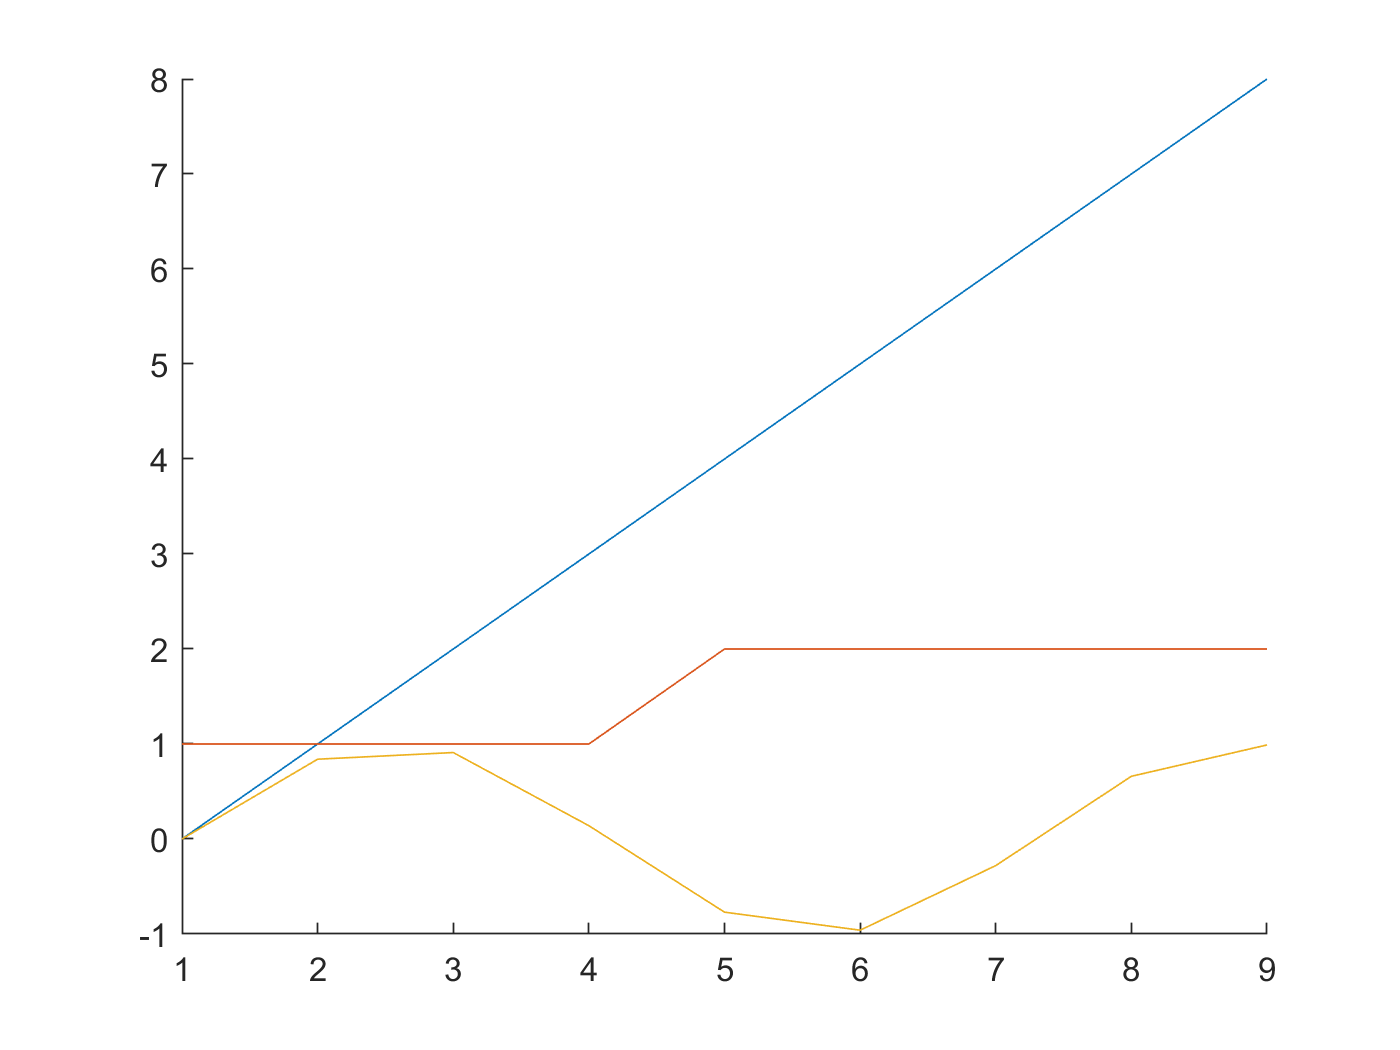

a = [0 1 2 3 4 5 6 7 8];
b = [1 1 1 1 2 2 2 2 2];
x = [a;b];
t = [0 0.84 0.91 0.14 -0.77 -0.96 -0.28 0.66 0.99];
figure; hold on; plot(a); plot(b); plot(t); hold off  

Here `feedforwardnet` creates a two-layer feed-forward network. The network has one hidden layer with ten neurons.

net = feedforwardnet(10);
net = configure(net,x,t);
y1 = net(x)

y1 =    -0.2289    0.1296    0.2038    0.0520   -0.7464   -0.1964   -0.0659   -0.1950   -0.0466


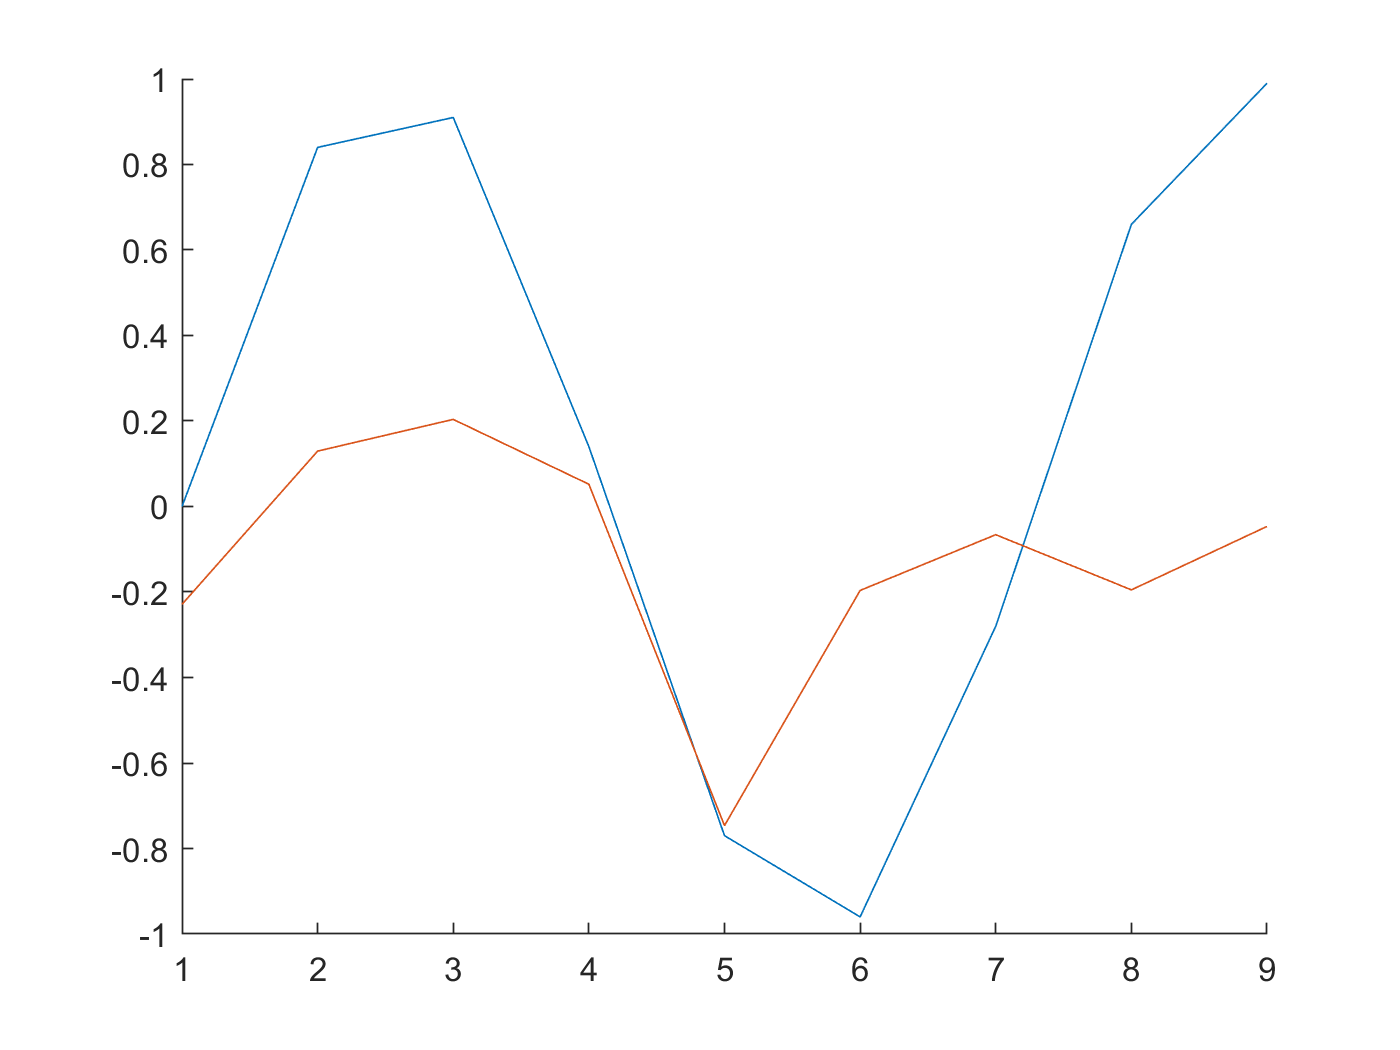

%plot(x,t,'o',x,y1,'x')
figure; hold on; plot(t); plot(y1); hold off  

The network is trained and then resimulated.

net = train(net,x,t);
y2 = net(x)

y2 =     0.0791    0.2491    0.2867   -0.4331   -0.2605   -0.5354   -0.3636    0.3085    1.7068


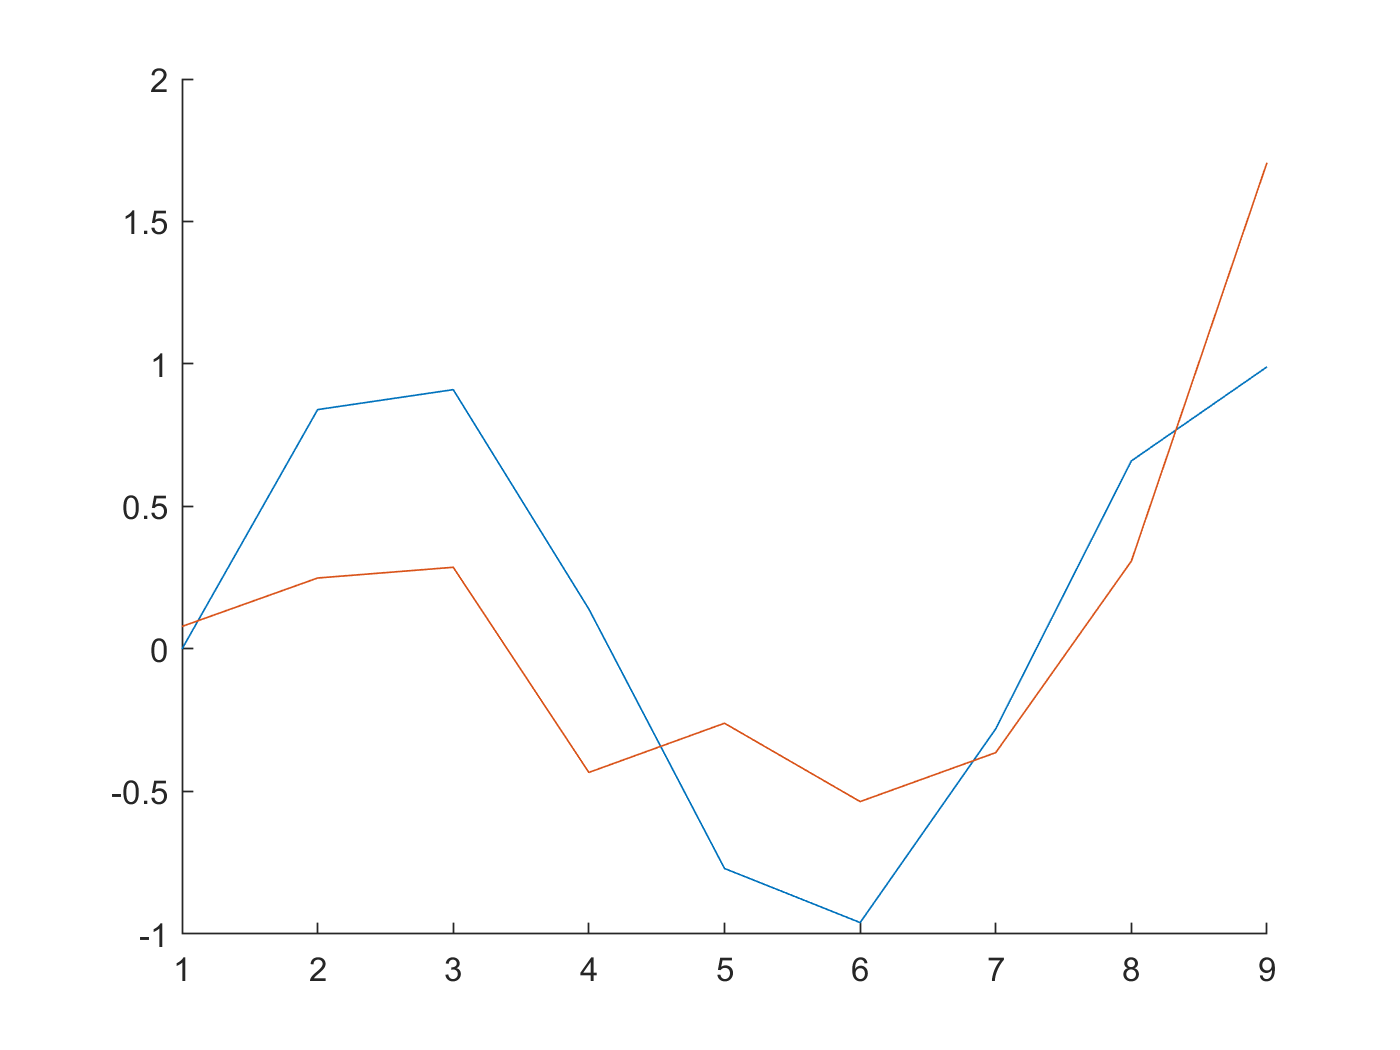

%plot(x,t,'o',x,y1,'x',x,y2,'*')
figure; hold on; plot(t); plot(y2); hold off  

# 저장된 데이타를 모두 읽어들인다.

clear
load ryan_gen_data  


# x = 05plus06plus07 y = pattern  - 출력값 = 유저패턴 = drop voltage 

BatteryNum = 56731;
Train_Input = x_05plus06plus07;
Train_Output = yPattern_05plus06plus07;

- FNN with 10 hidden neurons.

netFNN10 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN10.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN10, tr] = train(netFNN10, Train_Input', Train_Output', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


- FNN with 40 hidden neurons.

netFNN40 = feedforwardnet(40);
netFNN40.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN40.divideParam.trainInd = tr.trainInd;
netFNN40.divideParam.valInd = tr.valInd;
netFNN40.divideParam.testInd = tr.testInd;
netFNN40.trainParam.epochs = 300;
netFNN40 = train(netFNN40, Train_Input', Train_Output', 'useparallel', 'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |         0.30 |         0.34 |       0.0441 |       0.0583 |          0.0010 |
|      13 |          50 |       00:00:04 |         0.15 |         0.15 |       0.0106 |       0.0107 |          0.0010 |
|      25 |         100 |       00:00:06 |         0.15 |         0.15 |       0.0114 |       0.0109 |          0.0010 |
|      38 |         150 |       00:00:06 |         0.14 |         0.15 |       0.0096 |   

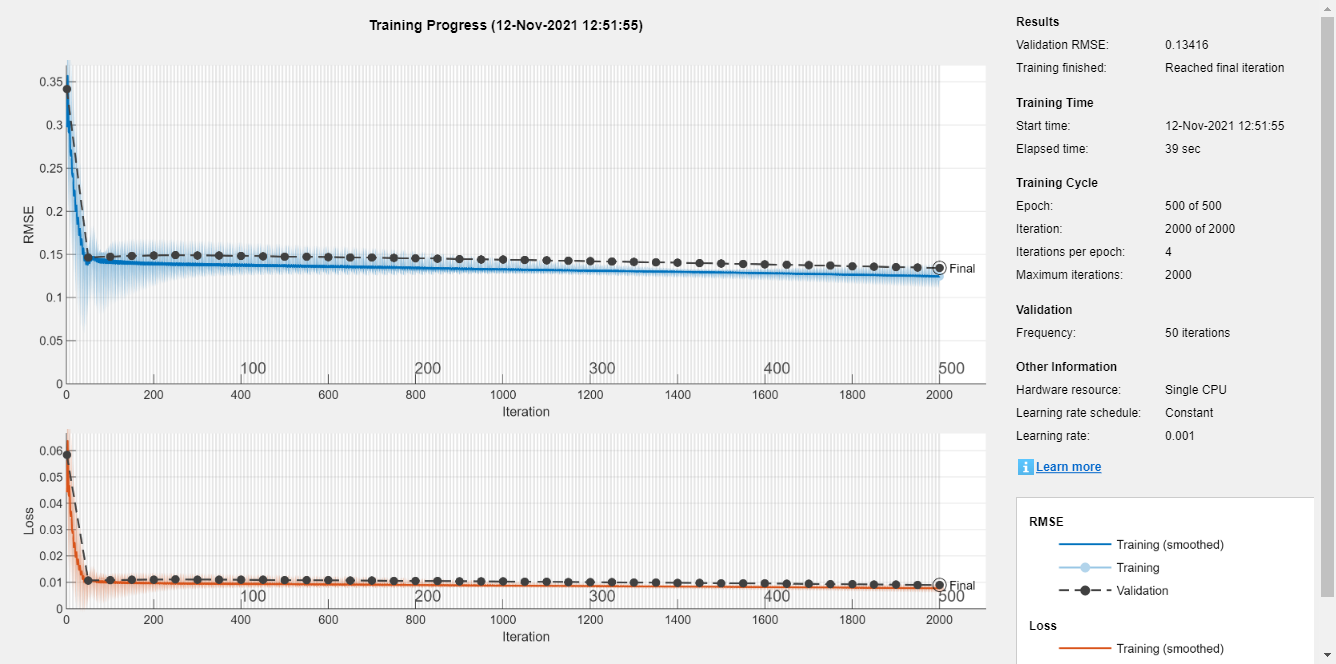

layerCNN1 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], 10, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 5, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
cellx = num2cell(Train_Input', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(Train_Output);
tbl = table(cellx);
tbl.cellyB = cellyB;

Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', valtbl);

netCNN1 = trainNetwork(Traintbl, layerCNN1, options);

- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |         0.18 |         0.17 |       0.0155 |       0.0137 |          0.0010 |
|      13 |          50 |       00:00:05 |         0.14 |         0.14 |       0.0092 |       0.0104 |          0.0010 |
|      25 |         100 |       00:00:06 |         0.14 |         0.14 |       0.0095 |       0.0103 |          0.0010 |
|      38 |         150 |       00:00:07 |         0.13 |         0.14 |       0.0081 |   

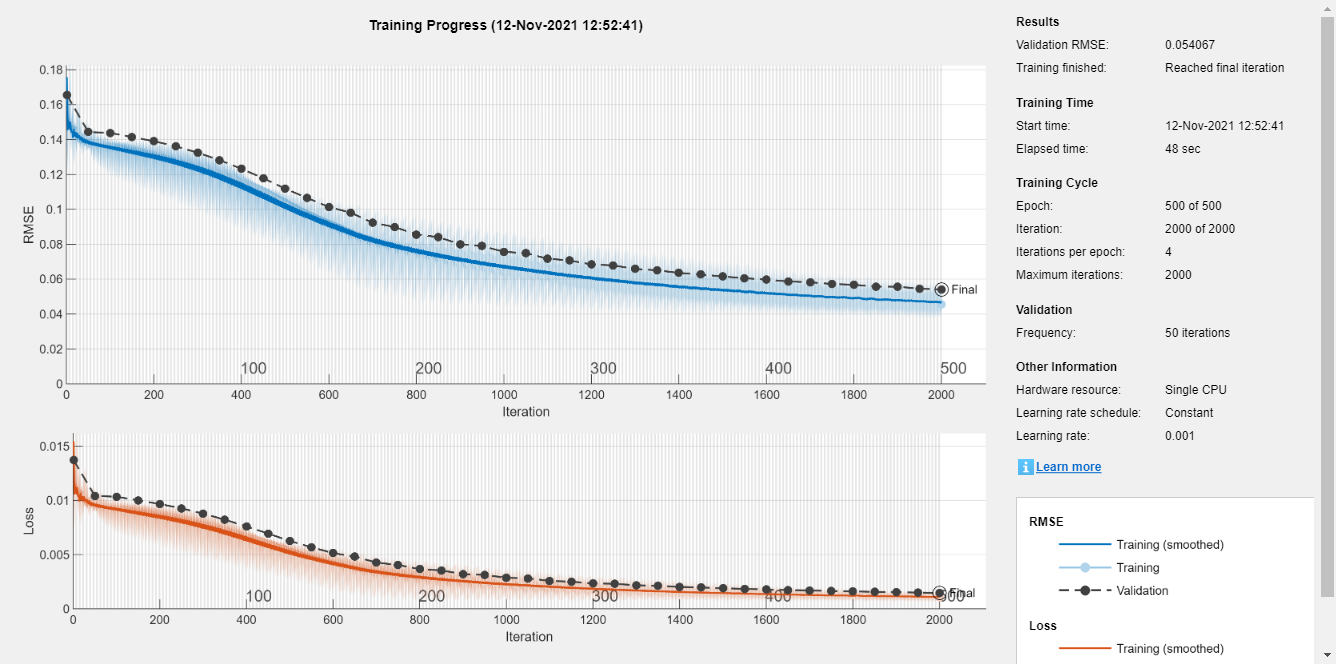

layerCNN2 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], charVIT_05plus06plus07_input_size, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], round(charVIT_05plus06plus07_input_size / 2) , 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
netCNN2 = trainNetwork(Traintbl, layerCNN2, options);

- LSTM : 1 lstm layer with 50 hidden units

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |         0.14 |         0.16 |       0.0101 |       0.0135 |          0.0010 |
|      13 |          50 |       00:00:06 |         0.14 |         0.15 |       0.0104 |       0.0109 |          0.0010 |
|      25 |         100 |       00:00:07 |         0.15 |         0.15 |       0.0113 |       0.0108 |          0.0010 |
|      38 |         150 |       00:00:08 |         0.14 |         0.15 |       0.0095 |       0.0106 |          0.0010 |
|      5

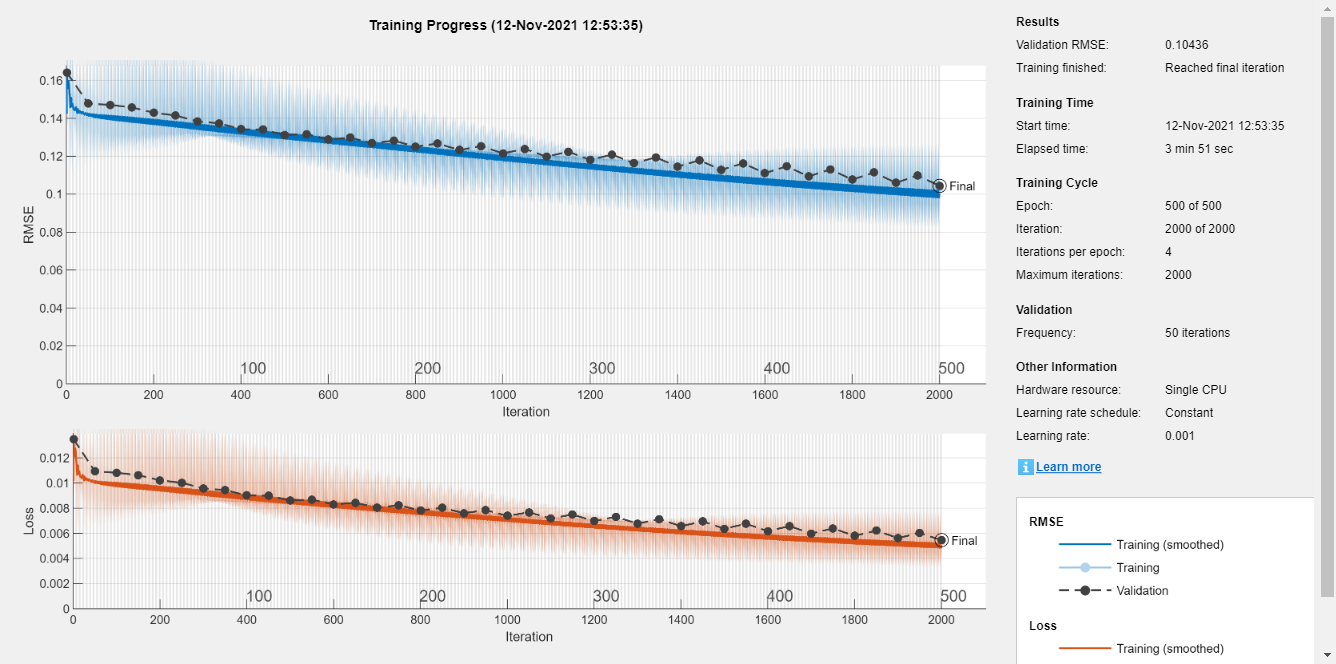

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layersLSTM = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

netLSTM = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## GRU

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:06 |         0.19 |         0.18 |       0.0176 |       0.0169 |          0.0010 |
|      13 |          50 |       00:00:09 |         0.14 |         0.15 |       0.0100 |       0.0106 |          0.0010 |
|      25 |         100 |       00:00:10 |         0.15 |         0.15 |       0.0117 |       0.0105 |          0.0010 |
|      38 |         150 |       00:00:11 |         0.14 |         0.14 |       0.0094 |       0.0105 |          0.0010 |
|      5

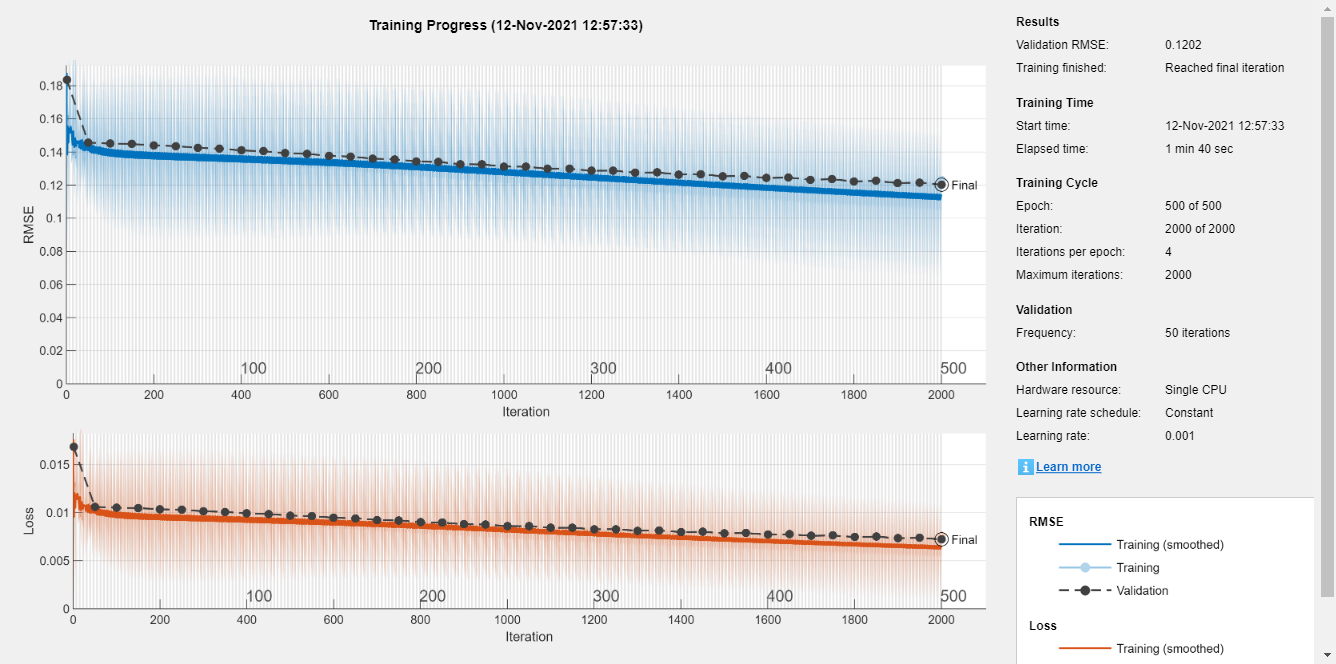

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layeGRU = [ ...
    sequenceInputLayer(inputSize)
    gruLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

%netGRU.trainParam.showWindow=0;
netGRU = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## Save model 

% https://kr.mathworks.com/matlabceloadntral/answers/264160-how-to-save-and-reuse-a-trained-neural-network

netFNN40_05plus06plus07_pattern_v2 = netFNN40;
netCNN1_05plus06plus07_pattern_v2 = netCNN1;
netCNN2_05plus06plus07_pattern_v2 = netCNN2;
netLSTM_05plus06plus07_pattern_v2 = netLSTM;
netGRU_05plus06plus07_pattern_v2 = netGRU;



### Prediciton using each 5 trained model

Make a prediction using trained models

pFNN40 = netFNN40(Train_Input(tr.testInd, :)');

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

cellx = num2cell(Train_Input(tr.testInd, :)', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);

x_4d = zeros(1, charVIT_05plus06plus07_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


pCNN1 = predict(netCNN1, x_4d);

- CNN2 : 2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

pCNN2 = predict(netCNN2, x_4d);

- LSTM : 1 lstm layer with 100 hidden units

pLSTM = cell2mat(predict(netLSTM, num2cell(Train_Input(tr.testInd, :)', 1)));

- GRU : 1 gru layer with 100 hidden units

pGRU = cell2mat(predict(netGRU, num2cell(Train_Input(tr.testInd, :)', 1)));

Denormalization for graphical ouput. Multiplying the range of original and add minimum value.

Train_Output = Train_Output(tr.testInd, :)*pattern_all_rate + pattern_all_min;
pFNN40 = pFNN40*pattern_all_rate + pattern_all_min;
pCNN1 = pCNN1*pattern_all_rate + pattern_all_min;
pCNN2 = pCNN2*pattern_all_rate + pattern_all_min;

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


pLSTM = pLSTM*pattern_all_rate + pattern_all_min;
pGRU = pGRU*pattern_all_rate + pattern_all_min;

### Result visualization

Visualize the prediction result. Battery capacity estimation based multi-channel charing profiles, using Voltage, Current and temperature.

total_cycle = length(Train_Output);
figure, hold on, grid on,
plot(Train_Output, 'linewidth', 2), plot(pFNN40, '^--'), plot(pCNN1, 'o--'), plot(pCNN2, 'x--'), plot(pLSTM, '-.'),plot(pGRU, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', '5+6+7', ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')


RMSE

rmse_pFNN40 = sqrt(mean(( Train_Output' - pFNN40 ).^2))
rmse_pCNN1  = sqrt(mean(( Train_Output' - pCNN1' ).^2))
rmse_pCNN2  = sqrt(mean(( Train_Output' - pCNN2' ).^2))
rmse_pLSTM  = sqrt(mean(( Train_Output' - pLSTM' ).^2))
rmse_pGRU = sqrt(mean(( Train_Output' - pGRU' ).^2))

### Prediciton #56 by model #5+#6+#7 pattern - Full Data = FNN40 에서 패턴 데이타를 잘 예측함.

%{
load  netFNN40_05plus06plus07_pattern_v2 

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |         0.14 |         0.13 |       0.0100 |       0.0086 |          0.0010 |
|      13 |          50 |       00:00:08 |         0.03 |         0.03 |       0.0004 |       0.0005 |          0.0010 |
|      25 |         100 |       00:00:10 |         0.02 |         0.03 |       0.0003 |       0.0004 |          0.0010 |
|      38 |         150 |       00:00:11 |         0.02 |         0.03 |       0.0003 |   

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |         0.27 |         0.25 |       0.0369 |       0.0301 |          0.0010 |
|      13 |          50 |       00:00:06 |         0.05 |         0.06 |       0.0013 |       0.0016 |          0.0010 |
|      25 |         100 |       00:00:07 |         0.03 |         0.03 |       0.0004 |       0.0005 |          0.0010 |
|      38 |         150 |       00:00:09 |         0.02 |         0.03 |       0.0003 |   

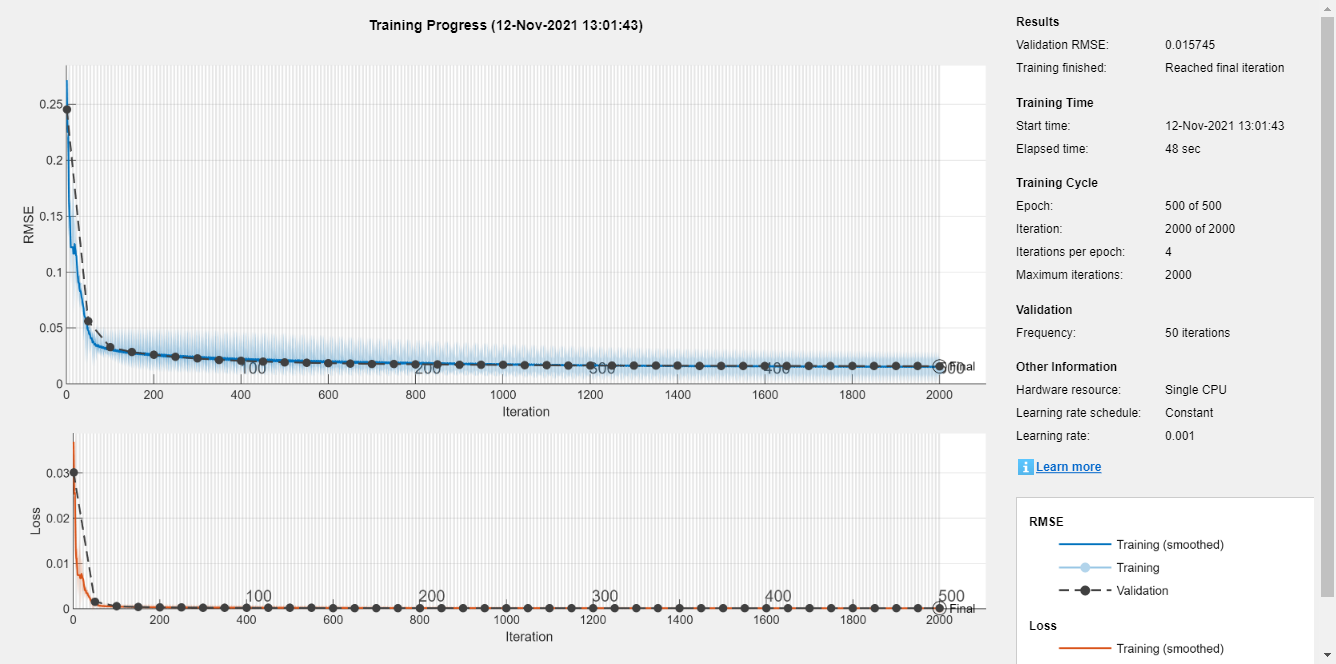

load  netCNN1_05plus06plus07_pattern_v2 
load  netCNN2_05plus06plus07_pattern_v2 
load  netLSTM_05plus06plus07_pattern_v2 
load  netGRU_05plus06plus07_pattern_v2 
%}

BatteryNum = 56;
pFNN40_0506 = netFNN40_05plus06plus07_pattern_v2(x_0506');
total_cycle = length(pFNN40_0506);
cellx = num2cell(x_0506', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);

tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0506 = predict(netCNN1_05plus06plus07_pattern_v2, x_4d);
pCNN2_0506 = predict(netCNN2_05plus06plus07_pattern_v2, x_4d);
pLSTM_0506 = cell2mat(predict(netLSTM_05plus06plus07_pattern_v2, num2cell(x_0506', 1)));
pGRU_0506 = cell2mat(predict(netGRU_05plus06plus07_pattern_v2, num2cell(x_0506', 1)));

y_0506 = yPattern_0506 *pattern_all_rate + pattern_all_min ;
pFNN40_0506 = pFNN40_0506 *pattern_all_rate + pattern_all_min ;
pCNN1_0506 = pCNN1_0506 *pattern_all_rate + pattern_all_min ;
pCNN2_0506 = pCNN2_0506 *pattern_all_rate + pattern_all_min ;
pLSTM_0506 = pLSTM_0506 *pattern_all_rate + pattern_all_min ;
pGRU_0506 = pGRU_0506 *pattern_all_rate + pattern_all_min ;

figure, hold on, grid on,
plot(y_0506, 'linewidth', 2), plot(pFNN40_0506, '^--'), plot(pCNN1_0506, 'o--'), plot(pCNN2_0506, 'x--'), plot(pLSTM_0506, '-.'),plot(pGRU_0506, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |         0.18 |         0.15 |       0.0168 |       0.0114 |          0.0010 |
|      13 |          50 |       00:00:04 |         0.04 |         0.04 |       0.0008 |       0.0007 |          0.0010 |
|      25 |         100 |       00:00:05 |         0.02 |         0.03 |       0.0002 |       0.0003 |          0.0010 |
|      38 |         150 |       00:00:06 |         0.02 |         0.03 |       0.0003 |       0.0003 |          0.0010 |
|      5

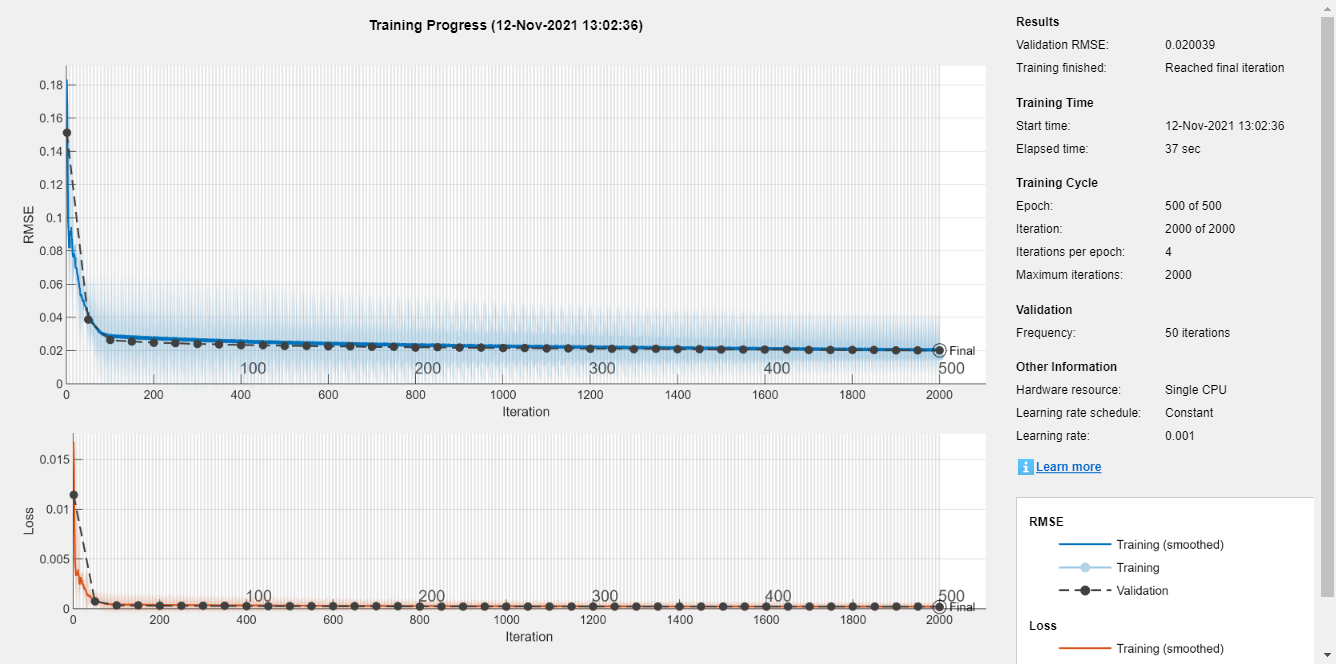


rmse_pFNN40_0506 = sqrt(mean(( y_0506(1:length(pFNN40_0506)) - pFNN40_0506').^2))

rmse_pCNN1_0506  = sqrt(mean(( y_0506 - pCNN1_0506 ).^2))
rmse_pCNN2_0506  = sqrt(mean(( y_0506 - pCNN2_0506 ).^2))
rmse_pLSTM_0506  = sqrt(mean(( y_0506 - pLSTM_0506 ).^2))
rmse_pGRU_0506   = sqrt(mean(( y_0506 - pGRU_0506  ).^2))
rmse_pFNN40_0506
rmse_pCNN1_0506
rmse_pCNN2_0506
rmse_pLSTM_0506
rmse_pGRU_0506

### Prediciton #56 by model #5+#6+#7 - From Pattern Change Point

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |         0.30 |         0.24 |       0.0450 |       0.0298 |          0.0010 |
|      13 |          50 |       00:00:05 |         0.06 |         0.06 |       0.0020 |       0.0020 |          0.0010 |
|      25 |         100 |       00:00:06 |         0.03 |         0.04 |       0.0006 |       0.0006 |          0.0010 |
|      38 |         150 |       00:00:07 |         0.03 |         0.03 |       0.0004 |       0.0004 |          0.0010 |
|      5

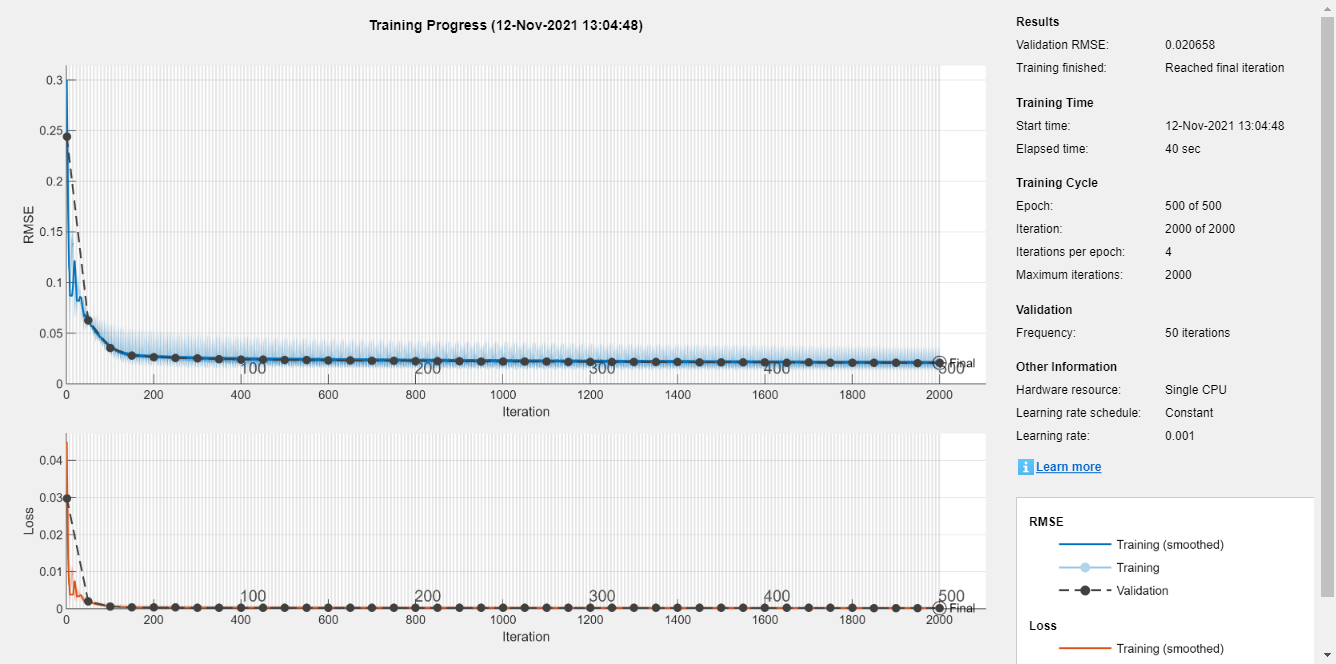


BatteryNum = 56;


pFNN40_0506 = netFNN40_05plus06plus07_pattern_v2(x_0506_change');   
total_cycle = length(pFNN40_0506);
cellx = num2cell(x_0506_change', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0506 = predict(netCNN1_05plus06plus07_pattern_v2, x_4d);
pCNN2_0506 = predict(netCNN2_05plus06plus07_pattern_v2, x_4d);
pLSTM_0506 = cell2mat(predict(netLSTM_05plus06plus07_pattern_v2, num2cell(x_0506_change', 1)));
pGRU_0506 = cell2mat(predict(netGRU_05plus06plus07_pattern_v2, num2cell(x_0506_change', 1)));

y_0506 = yPattern_0506 *pattern_all_rate + pattern_all_min ;

y_0506_change = y_0506(idx_0506:end);
pFNN40_0506_change = pFNN40_0506  *pattern_all_rate + pattern_all_min ;   pFNN40_0506 = [yPattern_0506_change_before    pFNN40_0506_change  ];
pCNN1_0506_change  = pCNN1_0506   *pattern_all_rate + pattern_all_min ;   pCNN1_0506  = [yPattern_0506_change_before' ; pCNN1_0506_change]  ;
pCNN2_0506_change  = pCNN2_0506   *pattern_all_rate + pattern_all_min ;   pCNN2_0506  = [yPattern_0506_change_before' ; pCNN2_0506_change   ];
pLSTM_0506_change  = pLSTM_0506   *pattern_all_rate + pattern_all_min ;   pLSTM_0506  = [yPattern_0506_change_before' ; pLSTM_0506_change   ];
pGRU_0506_change   = pGRU_0506    *pattern_all_rate + pattern_all_min ;    pGRU_0506  = [yPattern_0506_change_before' ; pGRU_0506_change    ];

figure, hold on, grid on,
plot(y_0506, 'linewidth', 2), plot(pFNN40_0506, '^--'), plot(pCNN1_0506, 'o--'), plot(pCNN2_0506, 'x--'), plot(pLSTM_0506, '-.'),plot(pGRU_0506, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_0506 = sqrt(mean(( y_0506_change(1:length(pFNN40_0506_change'))' - pFNN40_0506_change' ).^2))
rmse_pCNN1_0506  = sqrt(mean(( y_0506_change - pCNN1_0506_change ).^2))
rmse_pCNN2_0506  = sqrt(mean(( y_0506_change - pCNN2_0506_change ).^2))
rmse_pLSTM_0506  = sqrt(mean(( y_0506_change - pLSTM_0506_change ).^2))
rmse_pGRU_0506   = sqrt(mean(( y_0506_change - pGRU_0506_change  ).^2))

rmse_pFNN40_0506
rmse_pCNN1_0506
rmse_pCNN2_0506
rmse_pLSTM_0506
rmse_pGRU_0506

# x = 05plus06plus07 y = cap 

BatteryNum = 5673;
Train_Input = x_05plus06plus07;
Train_Output = yCap_05plus06plus07;

- FNN with 10 hidden neurons.

netFNN10 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN10.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN10, tr] = train(netFNN10, Train_Input', Train_Output', 'useparallel',  'yes');

- FNN with 40 hidden neurons.

netFNN40 = feedforwardnet(40);
netFNN40.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN40.divideParam.trainInd = tr.trainInd;
netFNN40.divideParam.valInd = tr.valInd;
netFNN40.divideParam.testInd = tr.testInd;
netFNN40.trainParam.epochs = 300;
netFNN40 = train(netFNN40, Train_Input', Train_Output', 'useparallel', 'yes');

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

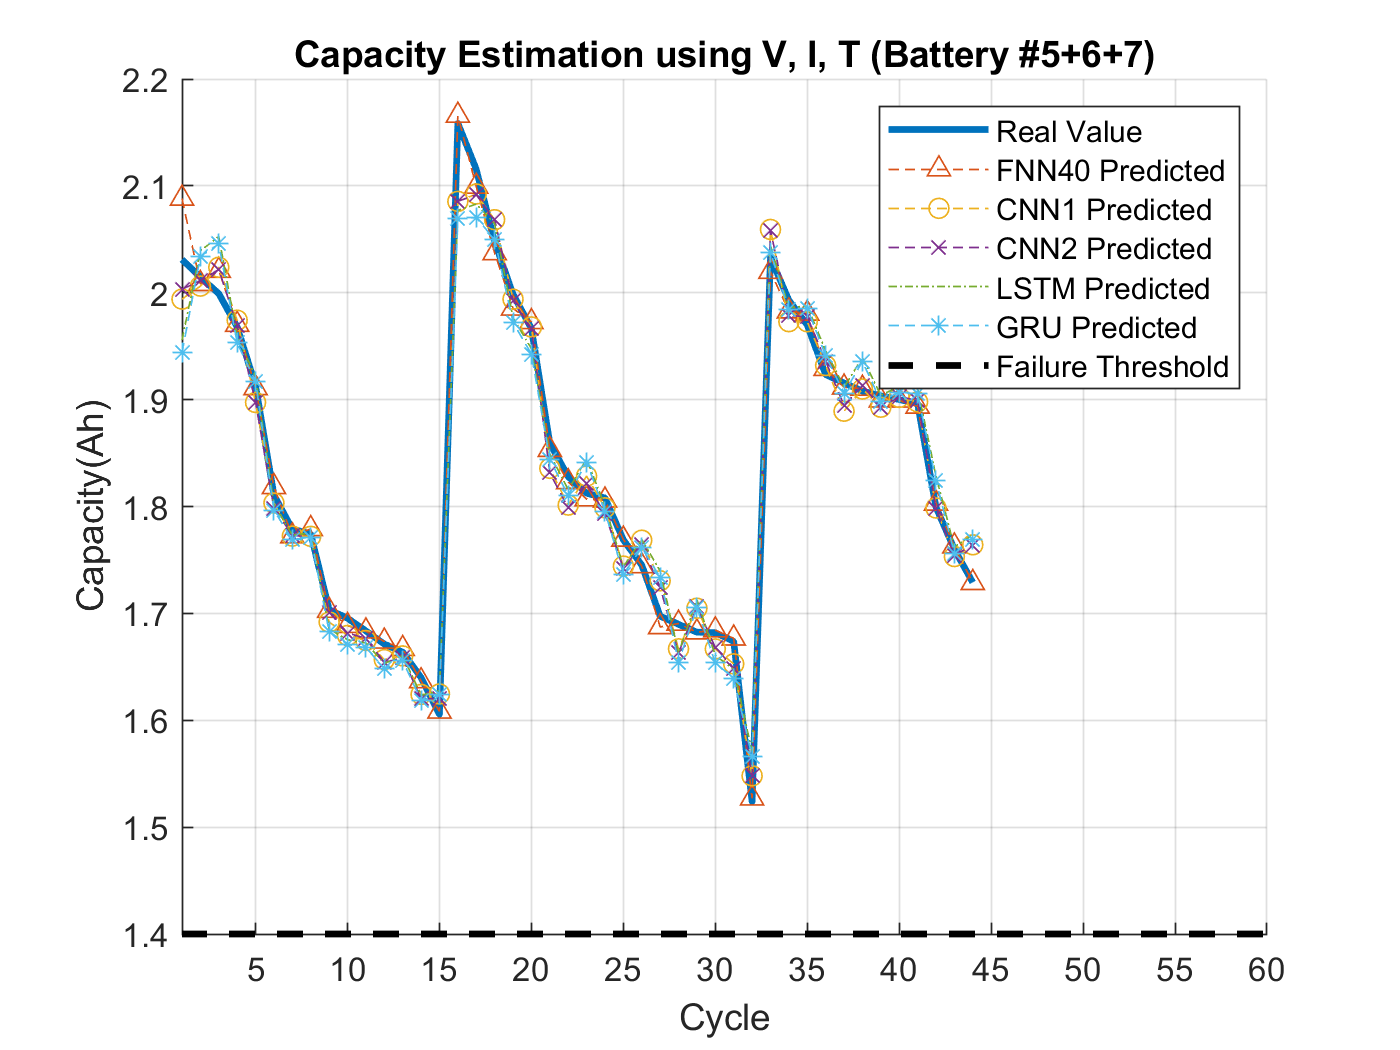

layerCNN1 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], 10, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 5, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)

    regressionLayer();
    ];
cellx = num2cell(Train_Input', 1)';

rmse_pFNN40 = 0.0110

cellx = cellfun(@transpose, cellx, 'UniformOutput', false);

rmse_pCNN1 = single
0.0211

cellyB = num2cell(Train_Output);

rmse_pCNN2 = single
0.0206

tbl = table(cellx);

rmse_pLSTM = single
0.0281

tbl.cellyB = cellyB;

rmse_pGRU = single
0.0295


Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', valtbl);

netCNN1 = trainNetwork(Traintbl, layerCNN1, options);

- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

layerCNN2 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], charVIT_05plus06plus07_input_size, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], round(charVIT_05plus06plus07_input_size / 2) , 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
netCNN2 = trainNetwork(Traintbl, layerCNN2, options);

- LSTM : 1 lstm layer with 50 hidden units

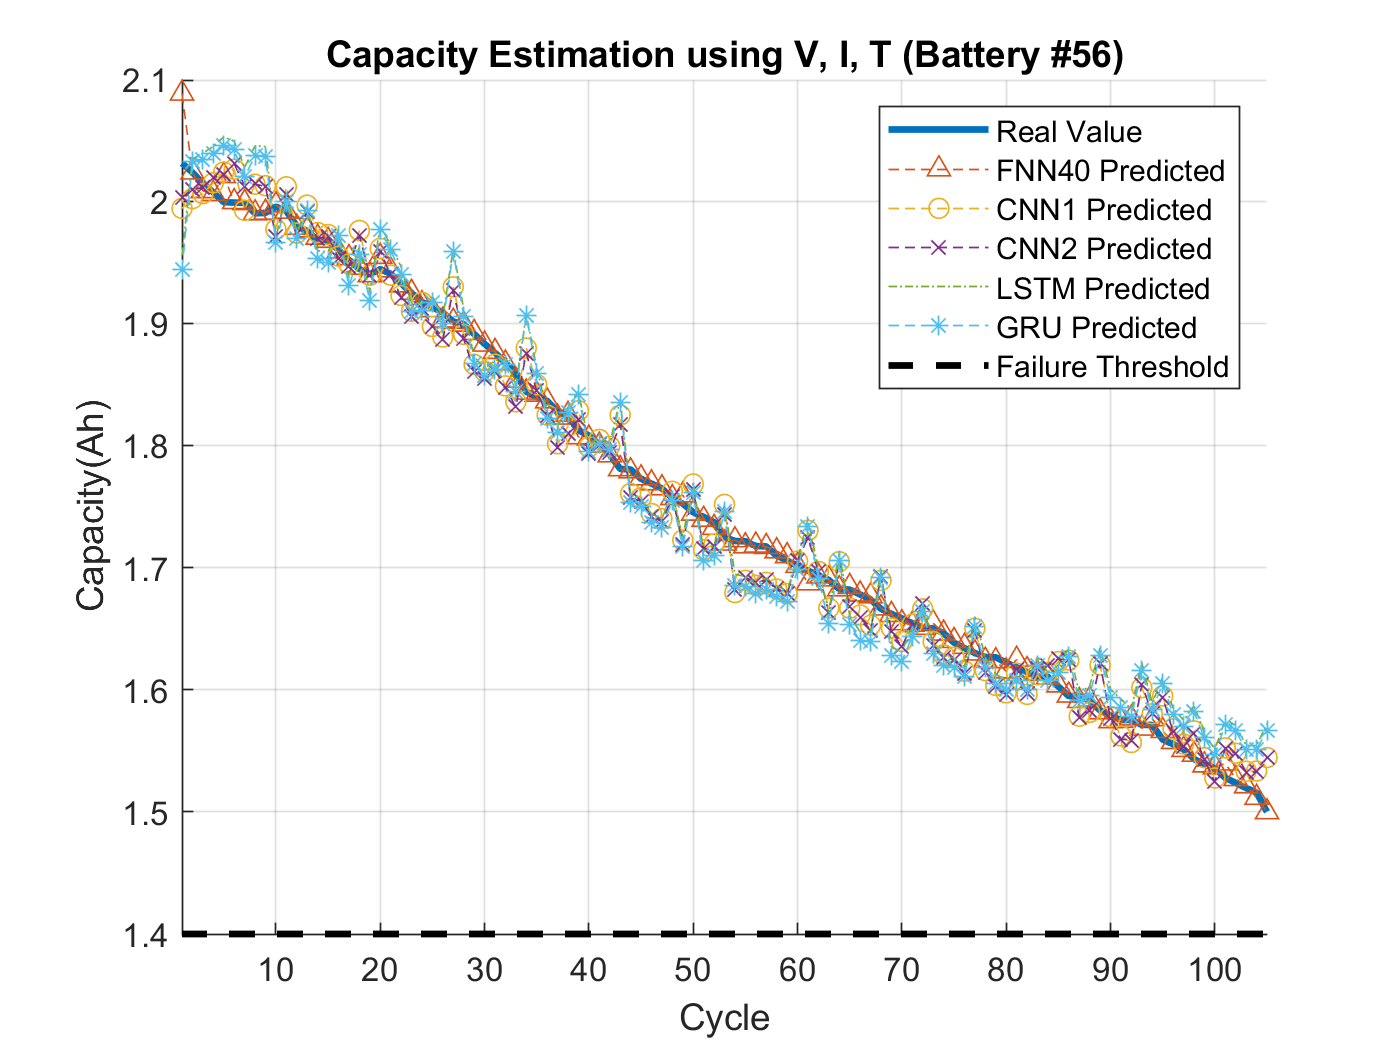

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layersLSTM = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);


traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);

rmse_pFNN40_0506 = 0.0068

testcellx = cellx(tr.testInd, :);

rmse_pCNN1_0506 = single
0.0206

rmse_pCNN2_0506 = single
0.0206

traincellyB = cellyB(tr.trainInd, :);

rmse_pLSTM_0506 = single
0.0287

valcellyB = cellyB(tr.valInd, :);

rmse_pGRU_0506 = single
0.0287

testcellyB = cellyB(tr.testInd, :);

rmse_pFNN40_0506 = 0.0068

rmse_pCNN1_0506 = single
0.0206

options = trainingOptions('adam', ...

rmse_pCNN2_0506 = single
0.0206

    'InitialLearnRate', 0.001, ...

rmse_pLSTM_0506 = single
0.0287

    'MaxEpochs',500, ...

rmse_pGRU_0506 = single
0.0287

    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

netLSTM = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## GRU

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layeGRU = [ ...
    sequenceInputLayer(inputSize)
    gruLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

%netGRU.trainParam.showWindow=0;
netGRU = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## Save model 

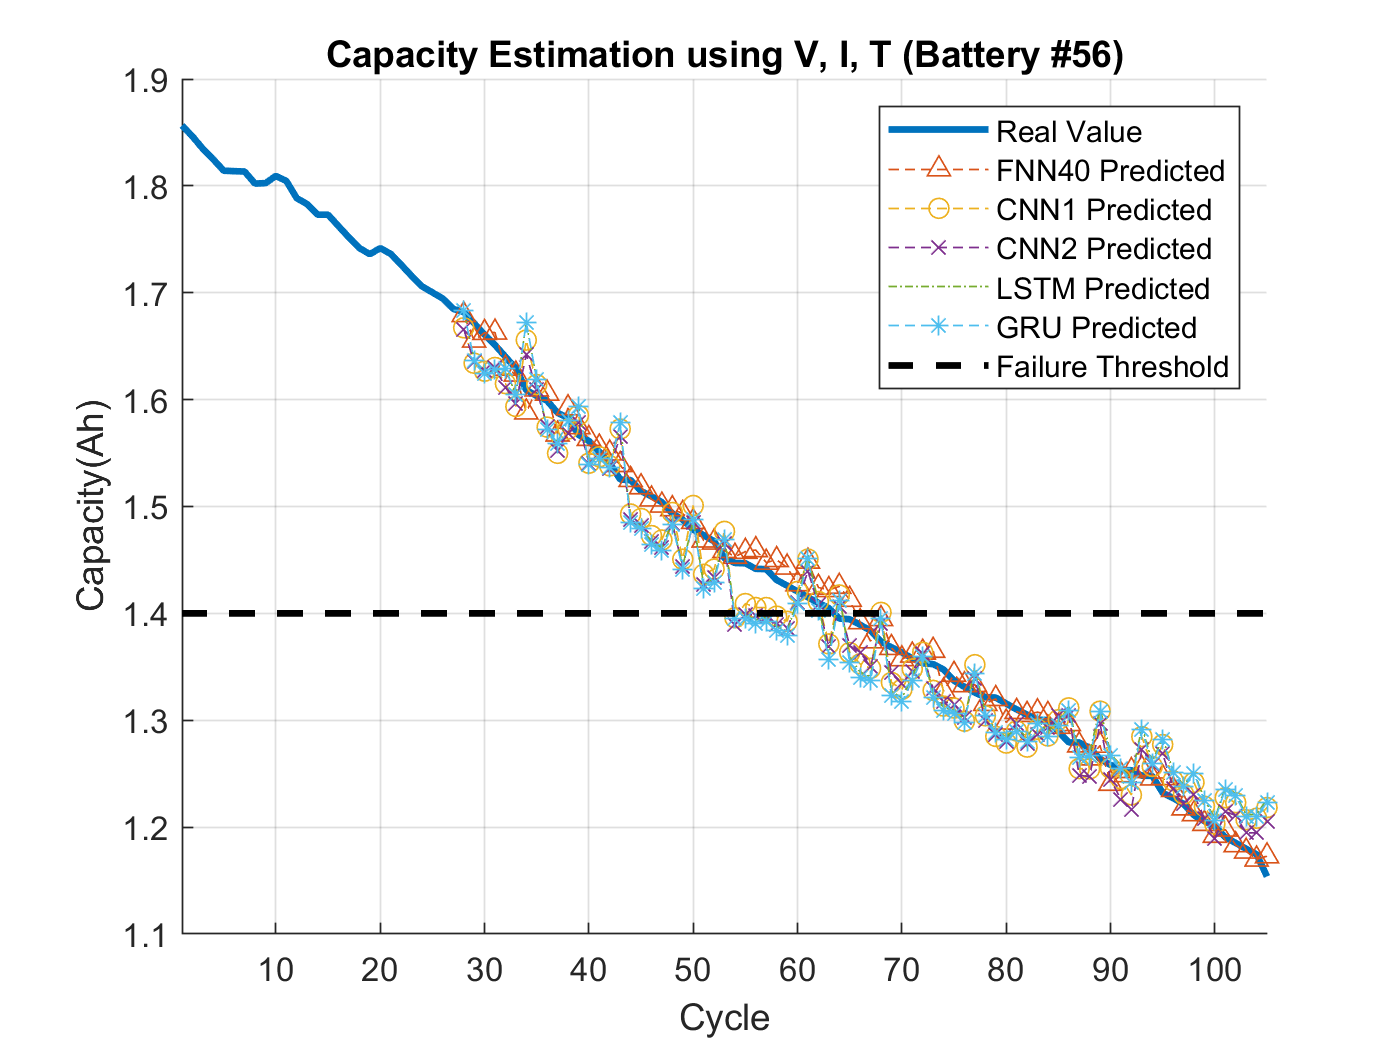

% https://kr.mathworks.com/matlabceloadntral/answers/264160-how-to-save-and-reuse-a-trained-neural-network

netFNN40_05plus06plus07_v2 = netFNN40;
netCNN1_05plus06plus07_v2 = netCNN1;

netCNN2_05plus06plus07_v2 = netCNN2;
netLSTM_05plus06plus07_v2 = netLSTM;

rmse_pFNN40_0506 = NaN

netGRU_05plus06plus07_v2 = netGRU;

rmse_pCNN1_0506 = single
NaN

rmse_pCNN2_0506 = single
NaN

rmse_pLSTM_0506 = single
NaN

rmse_pGRU_0506 = single
NaN

### Prediciton using each 5 trained model

Make a prediction using trained models

pFNN40 = netFNN40(Train_Input(tr.testInd, :)');

rmse_pFNN40_0506 = NaN

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

cellx = num2cell(Train_Input(tr.testInd, :)', 1)';

rmse_pCNN1_0506 = single
NaN

cellx = cellfun(@transpose, cellx, 'UniformOutput', false);

rmse_pCNN2_0506 = single
NaN

rmse_pLSTM_0506 = single
NaN

rmse_pGRU_0506 = single
NaN

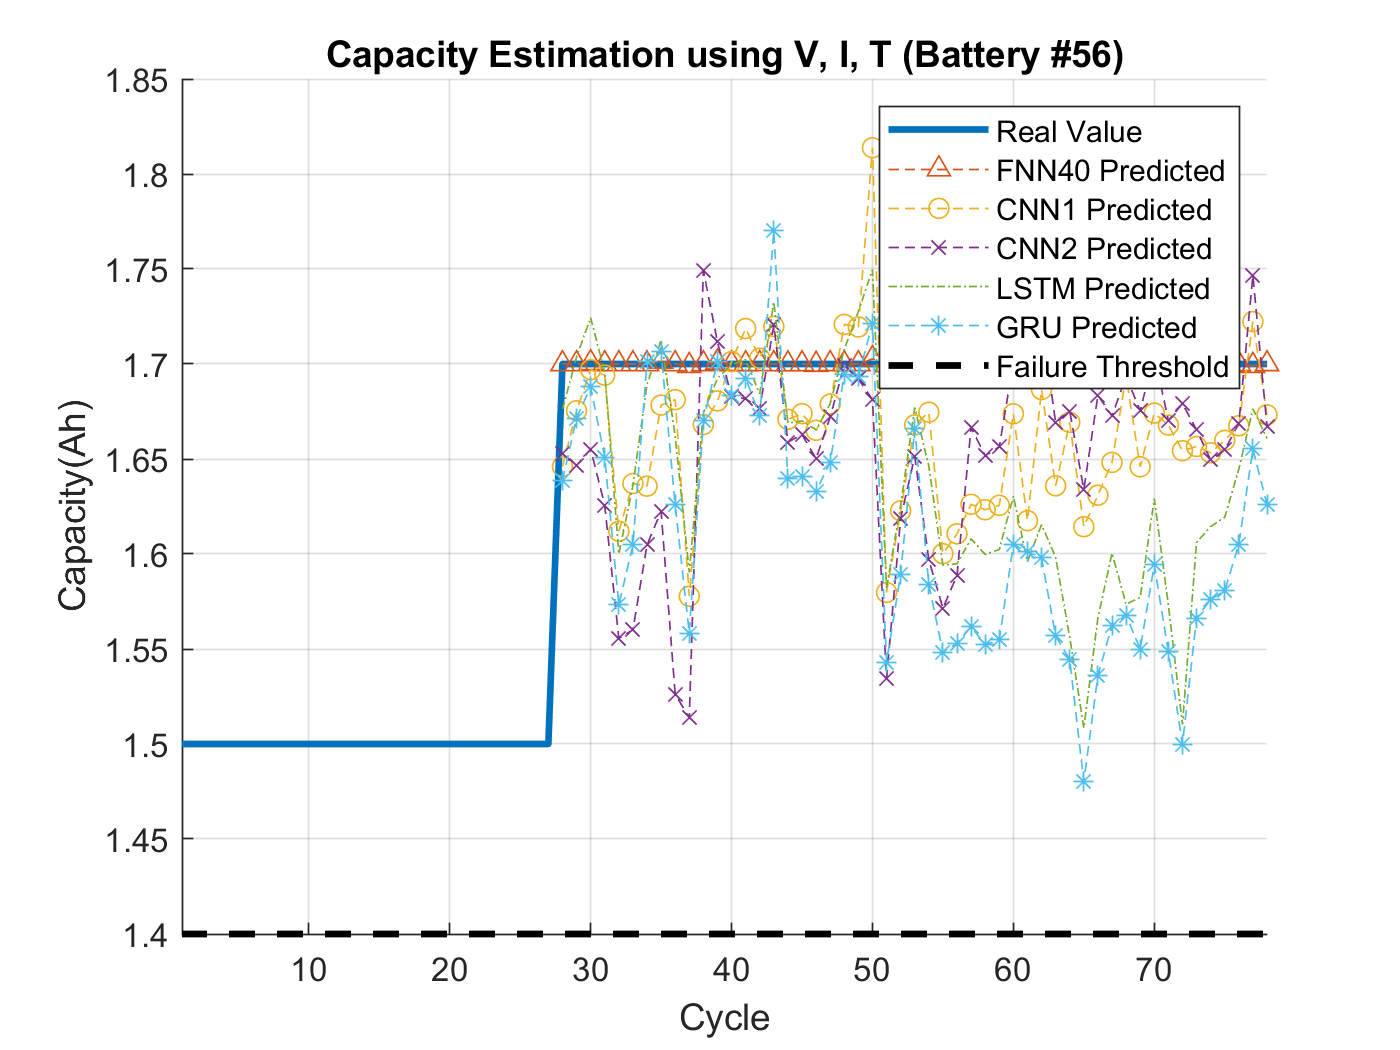

tbl = table(cellx);

x_4d = zeros(1, charVIT_05plus06plus07_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end
pCNN1 = predict(netCNN1, x_4d);

- CNN2 : 2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

pCNN2 = predict(netCNN2, x_4d);

- LSTM : 1 lstm layer with 100 hidden units

pLSTM = cell2mat(predict(netLSTM, num2cell(Train_Input(tr.testInd, :)', 1)));

- GRU : 1 gru layer with 100 hidden units

pGRU = cell2mat(predict(netGRU, num2cell(Train_Input(tr.testInd, :)', 1)));

Denormalization for graphical ouput. Multiplying the range of original and add minimum value.

Train_Output = Train_Output(tr.testInd, :)*cap_all_rate + cap_all_min;

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


pFNN40 = pFNN40*cap_all_rate + cap_all_min;
pCNN1 = pCNN1*cap_all_rate + cap_all_min;
pCNN2 = pCNN2*cap_all_rate + cap_all_min;
pLSTM = pLSTM*cap_all_rate + cap_all_min;
pGRU = pGRU*cap_all_rate + cap_all_min;

### Result visualization

Visualize the prediction result. Battery capacity estimation based multi-channel charing profiles, using Voltage, Current and temperature.

total_cycle = length(Train_Output);
figure, hold on, grid on,
plot(Train_Output, 'linewidth', 2), plot(pFNN40, '^--'), plot(pCNN1, 'o--'), plot(pCNN2, 'x--'), plot(pLSTM, '-.'),plot(pGRU, '*--'),

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', '5+6+7', ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

RMSE

rmse_pFNN40 = sqrt(mean(( Train_Output' - pFNN40 ).^2))
rmse_pCNN1  = sqrt(mean(( Train_Output' - pCNN1' ).^2))
rmse_pCNN2  = sqrt(mean(( Train_Output' - pCNN2' ).^2))
rmse_pLSTM  = sqrt(mean(( Train_Output' - pLSTM' ).^2))
rmse_pGRU = sqrt(mean(( Train_Output' - pGRU' ).^2))

### Prediciton #56 by model #5+#6+#7  

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |         0.14 |         0.19 |       0.0103 |       0.0180 |          0.0010 |
|      50 |          50 |       00:00:07 |         0.05 |         0.07 |       0.0014 |       0.0028 |          0.0010 |
|     100 |         100 |       00:00:08 |         0.01 |         0.01 |   9.2280e-05 |   5.7390e-05 |          0.0010 |
|     150 |         150 |       00:00:09 |         0.01 |         0.01 |   6.9777e-05 |   

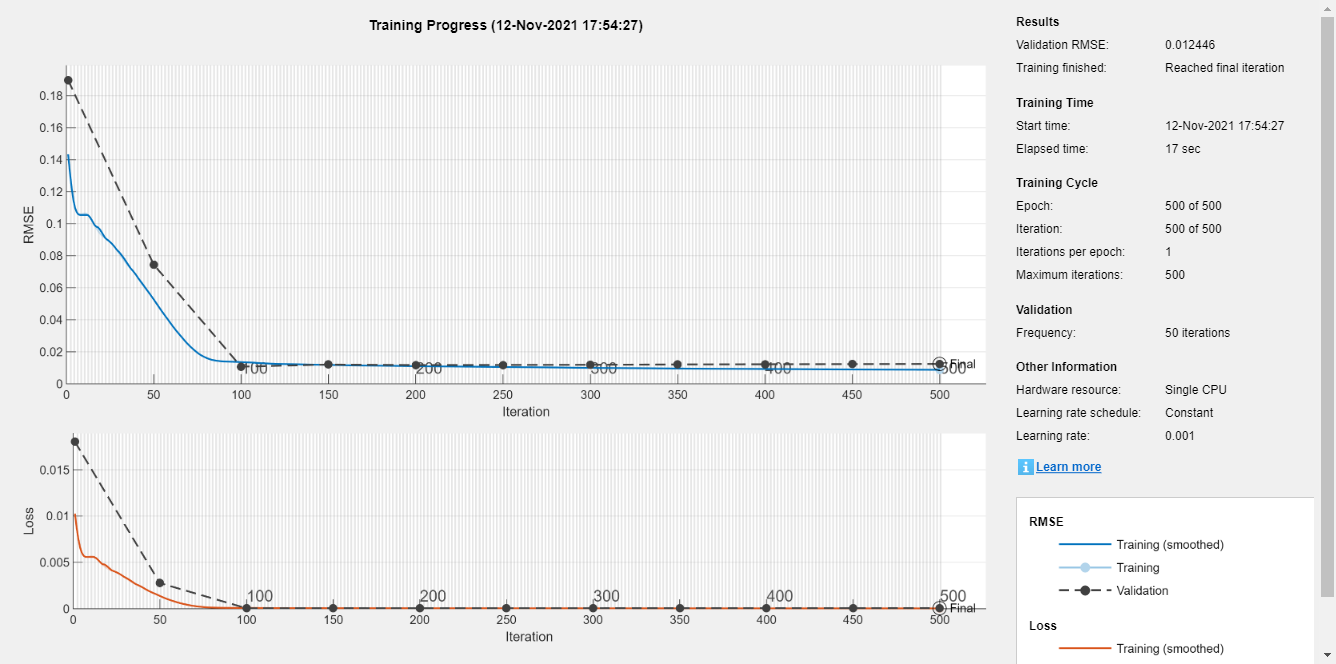


BatteryNum = 56;
pFNN40_0506 = netFNN40_05plus06plus07_v2(x_0506');
total_cycle = length(pFNN40_0506);
cellx = num2cell(x_0506', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |         0.17 |         0.19 |       0.0151 |       0.0181 |          0.0010 |
|      50 |          50 |       00:00:05 |         0.02 |         0.01 |       0.0003 |       0.0001 |          0.0010 |
|     100 |         100 |       00:00:06 |         0.02 |         0.02 |       0.0002 |       0.0001 |          0.0010 |
|     150 |         150 |       00:00:07 |         0.02 |         0.02 |       0.0001 |   

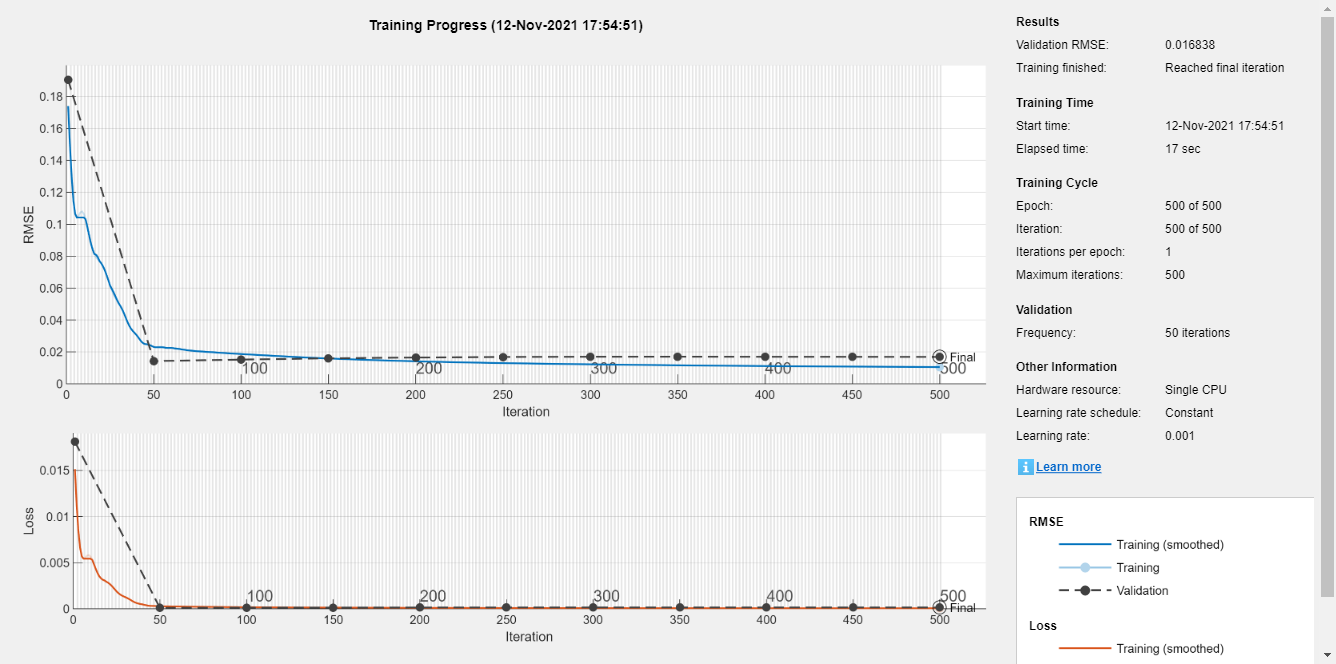


pCNN1_0506 = predict(netCNN1_05plus06plus07_v2, x_4d);
pCNN2_0506 = predict(netCNN2_05plus06plus07_v2, x_4d);
pLSTM_0506 = cell2mat(predict(netLSTM_05plus06plus07_v2, num2cell(x_0506', 1)));
pGRU_0506 = cell2mat(predict(netGRU_05plus06plus07_v2, num2cell(x_0506', 1)));

y_0506 = yCap_0506 *cap_all_rate + cap_all_min ;
pFNN40_0506 = pFNN40_0506 *cap_all_rate + cap_all_min ;
pCNN1_0506 = pCNN1_0506 *cap_all_rate + cap_all_min ;
pCNN2_0506 = pCNN2_0506 *cap_all_rate + cap_all_min ;
pLSTM_0506 = pLSTM_0506 *cap_all_rate + cap_all_min ;

pGRU_0506 = pGRU_0506 *cap_all_rate + cap_all_min ;

figure, hold on, grid on,
plot(y_0506, 'linewidth', 2), plot(pFNN40_0506, '^--'), plot(pCNN1_0506, 'o--'), plot(pCNN2_0506, 'x--'), plot(pLSTM_0506, '-.'),plot(pGRU_0506, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_0506 = sqrt(mean(( y_0506(1:length(pFNN40_0506)) - pFNN40_0506').^2))
rmse_pCNN1_0506  = sqrt(mean(( y_0506 - pCNN1_0506 ).^2))
rmse_pCNN2_0506  = sqrt(mean(( y_0506 - pCNN2_0506 ).^2))
rmse_pLSTM_0506  = sqrt(mean(( y_0506 - pLSTM_0506 ).^2))
rmse_pGRU_0506   = sqrt(mean(( y_0506 - pGRU_0506  ).^2))
rmse_pFNN40_0506
rmse_pCNN1_0506
rmse_pCNN2_0506
rmse_pLSTM_0506
rmse_pGRU_0506

## From Change point

x_0506 => x_0506_change

BatteryNum = 56;


Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |         0.26 |         0.26 |       0.0341 |       0.0329 |          0.0010 |
|      50 |          50 |       00:00:06 |         0.07 |         0.06 |       0.0023 |       0.0017 |          0.0010 |
|     100 |         100 |       00:00:08 |         0.04 |         0.03 |       0.0007 |       0.0006 |          0.0010 |
|     150 |         150 |       00:00:09 |         0.03 |         0.02 |       0.0003 |       0.0001 |          0.0010 |
|     20

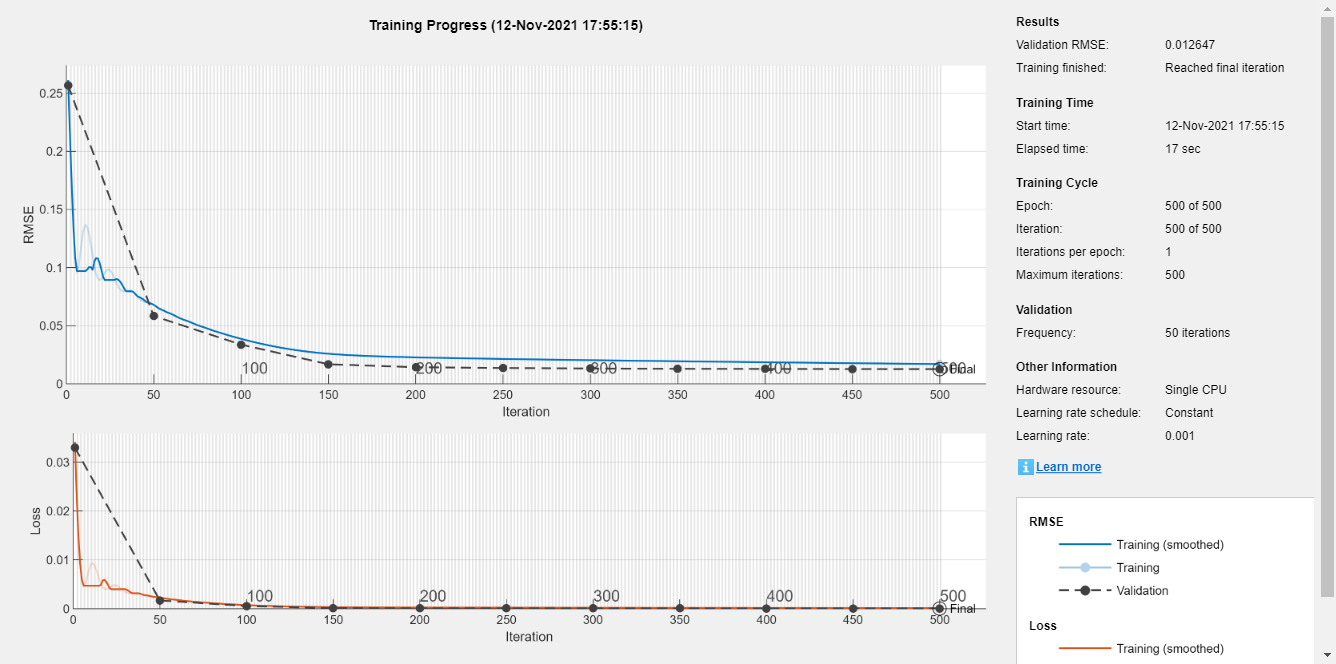


pFNN40_0506 = netFNN40_05plus06plus07_v2(x_0506_change');
cellx = num2cell(x_0506_change', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |         0.37 |         0.35 |       0.0685 |       0.0612 |          0.0010 |
|      50 |          50 |       00:00:05 |         0.07 |         0.05 |       0.0024 |       0.0014 |          0.0010 |
|     100 |         100 |       00:00:06 |         0.05 |         0.03 |       0.0010 |       0.0006 |          0.0010 |
|     150 |         150 |       00:00:07 |         0.03 |         0.02 |       0.0004 |       0.0002 |          0.0010 |
|     20

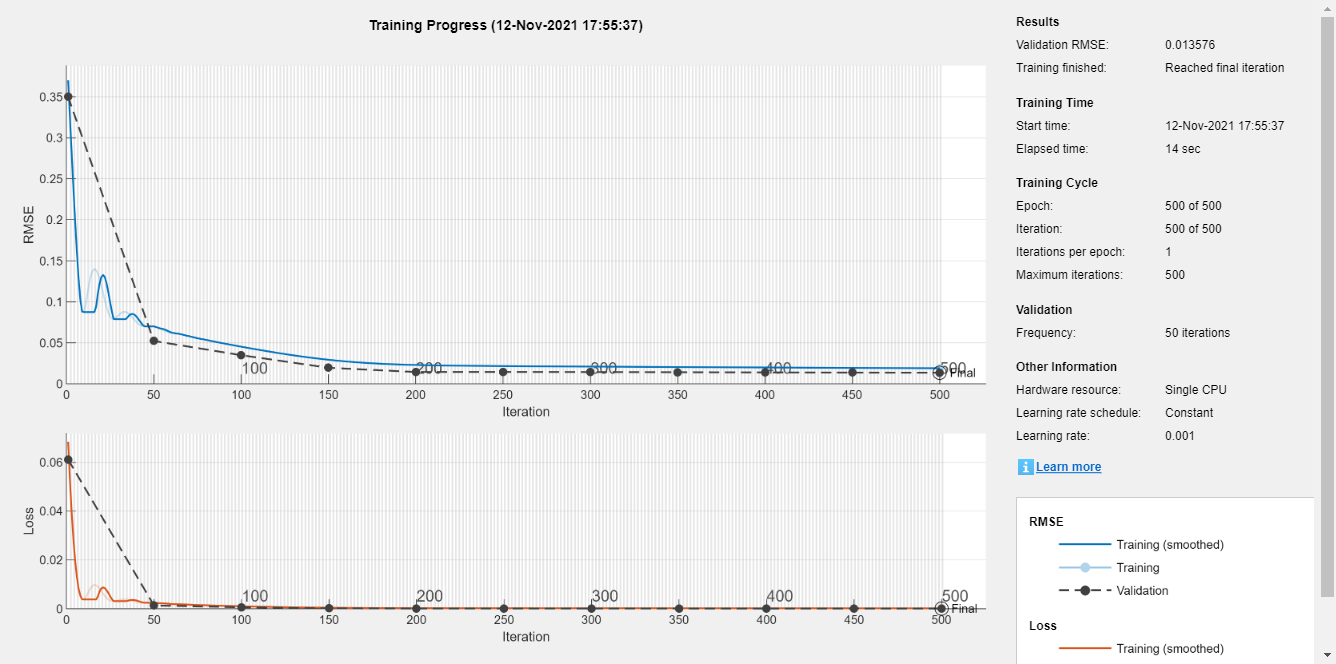

    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0506 = predict(netCNN1_05plus06plus07_v2, x_4d);
pCNN2_0506 = predict(netCNN2_05plus06plus07_v2, x_4d);
pLSTM_0506 = cell2mat(predict(netLSTM_05plus06plus07_v2, num2cell(x_0506_change', 1)));
pGRU_0506 = cell2mat(predict(netGRU_05plus06plus07_v2, num2cell(x_0506_change', 1)));

y_0506 = yCap_0506 *cap_all_rate + cap_all_min ;
total_cycle = length(y_0506);
y_0506_change = y_0506(idx_0506:end);
pFNN40_0506_change = pFNN40_0506  *cap_all_rate + cap_all_min ;   pFNN40_0506 = [yPattern_0506_change_before    pFNN40_0506_change  ];
pCNN1_0506_change  = pCNN1_0506   *cap_all_rate + cap_all_min ;   pCNN1_0506  = [yPattern_0506_change_before' ; pCNN1_0506_change]  ;
pCNN2_0506_change  = pCNN2_0506   *cap_all_rate + cap_all_min ;   pCNN2_0506  = [yPattern_0506_change_before' ; pCNN2_0506_change   ];
pLSTM_0506_change  = pLSTM_0506   *cap_all_rate + cap_all_min ;   pLSTM_0506  = [yPattern_0506_change_before' ; pLSTM_0506_change   ];
pGRU_0506_change   = pGRU_0506    *cap_all_rate + cap_all_min ;   pGRU_0506   = [yPattern_0506_change_before' ; pGRU_0506_change    ];
  
figure, hold on, grid on,
plot(y_0506, 'linewidth', 2), plot(pFNN40_0506, '^--'), plot(pCNN1_0506, 'o--'), plot(pCNN2_0506, 'x--'), plot(pLSTM_0506, '-.'),plot(pGRU_0506, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_0506 = sqrt(mean(( y_0506(1:length(pFNN40_0506)) - pFNN40_0506').^2))
rmse_pCNN1_0506  = sqrt(mean(( y_0506 - pCNN1_0506 ).^2))
rmse_pCNN2_0506  = sqrt(mean(( y_0506 - pCNN2_0506 ).^2))
rmse_pLSTM_0506  = sqrt(mean(( y_0506 - pLSTM_0506 ).^2))
rmse_pGRU_0506   = sqrt(mean(( y_0506 - pGRU_0506  ).^2))

rmse_pFNN40_0506
rmse_pCNN1_0506
rmse_pCNN2_0506
rmse_pLSTM_0506
rmse_pGRU_0506

# x = 05 y = cap 

BatteryNum = 5;
Train_Input = x_05;
Train_Output = yCap_05;

- FNN with 10 hidden neurons.

netFNN10 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN10.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN10, tr] = train(netFNN10, Train_Input', Train_Output', 'useparallel',  'yes');

- FNN with 40 hidden neurons.

netFNN40 = feedforwardnet(40);
netFNN40.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN40.divideParam.trainInd = tr.trainInd;
netFNN40.divideParam.valInd = tr.valInd;
netFNN40.divideParam.testInd = tr.testInd;
netFNN40.trainParam.epochs = 300;
netFNN40 = train(netFNN40, Train_Input', Train_Output', 'useparallel', 'yes');

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

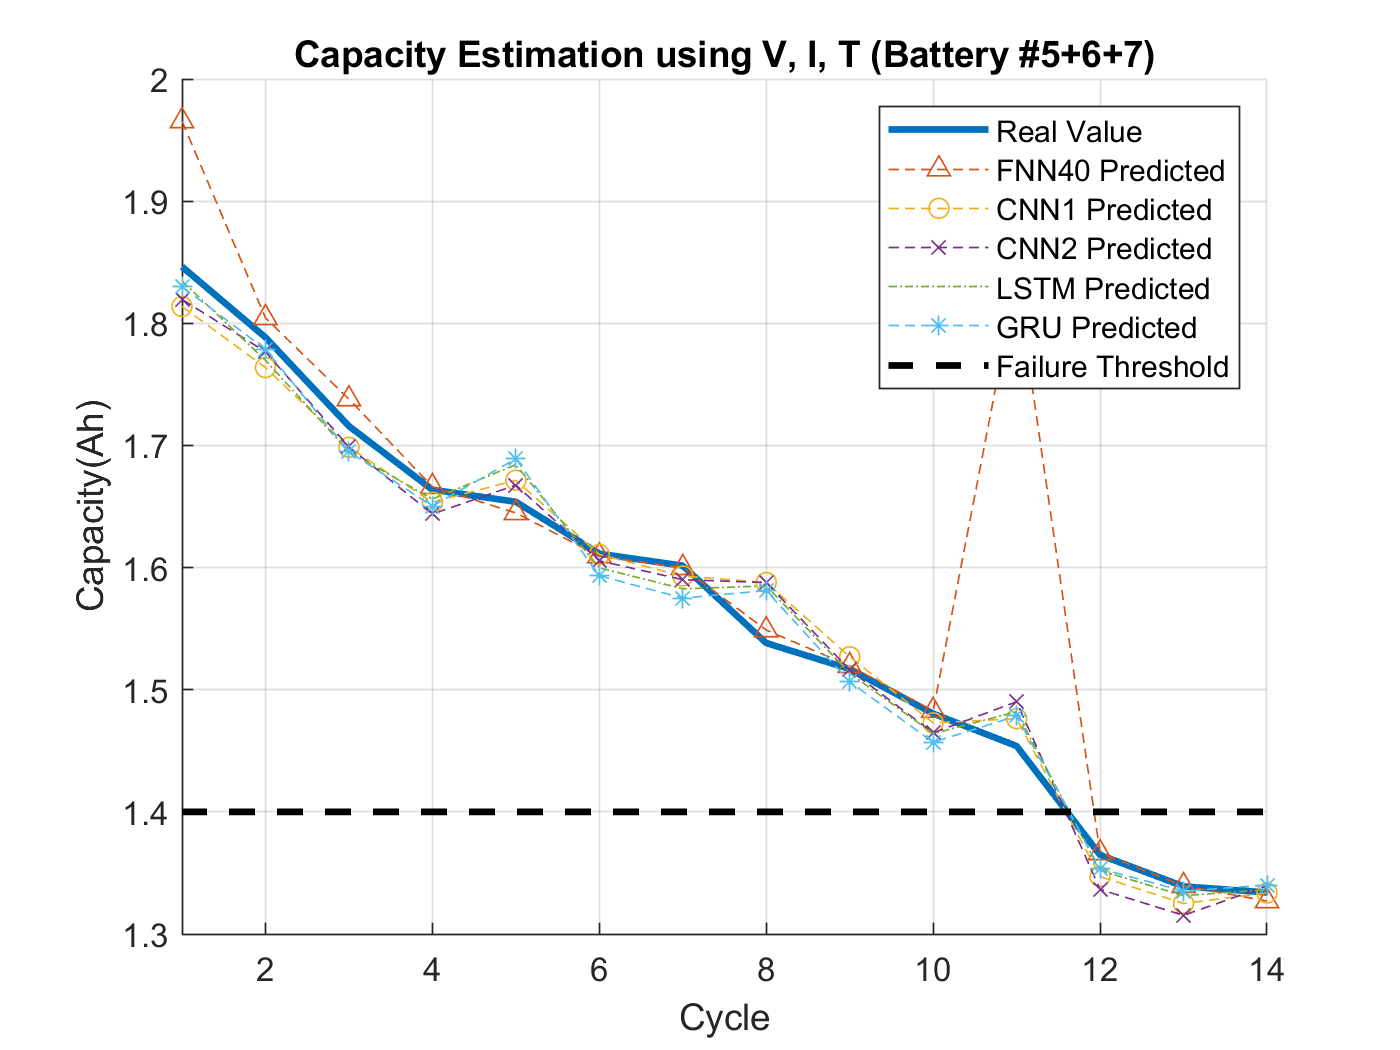

layerCNN1 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], 10, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 5, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
cellx = num2cell(Train_Input', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(Train_Output);
tbl = table(cellx);
tbl.cellyB = cellyB;

Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', valtbl);


netCNN1 = trainNetwork(Traintbl, layerCNN1, options);

- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

layerCNN2 = [

rmse_pFNN40 = 0.1073

    imageInputLayer([1, charVIT_05plus06plus07_input_size]);

rmse_pCNN1 = single
0.0208

    convolution2dLayer([1, 2], charVIT_05plus06plus07_input_size, 'Stride', 1);

rmse_pCNN2 = single
0.0228

    leakyReluLayer

rmse_pLSTM = single
0.0205

    convolution2dLayer([1, 2], round(charVIT_05plus06plus07_input_size / 2) , 'Stride', 1);

rmse_pGRU = single
0.0216

    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
netCNN2 = trainNetwork(Traintbl, layerCNN2, options);

- LSTM : 1 lstm layer with 50 hidden units

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layersLSTM = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

netLSTM = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## GRU

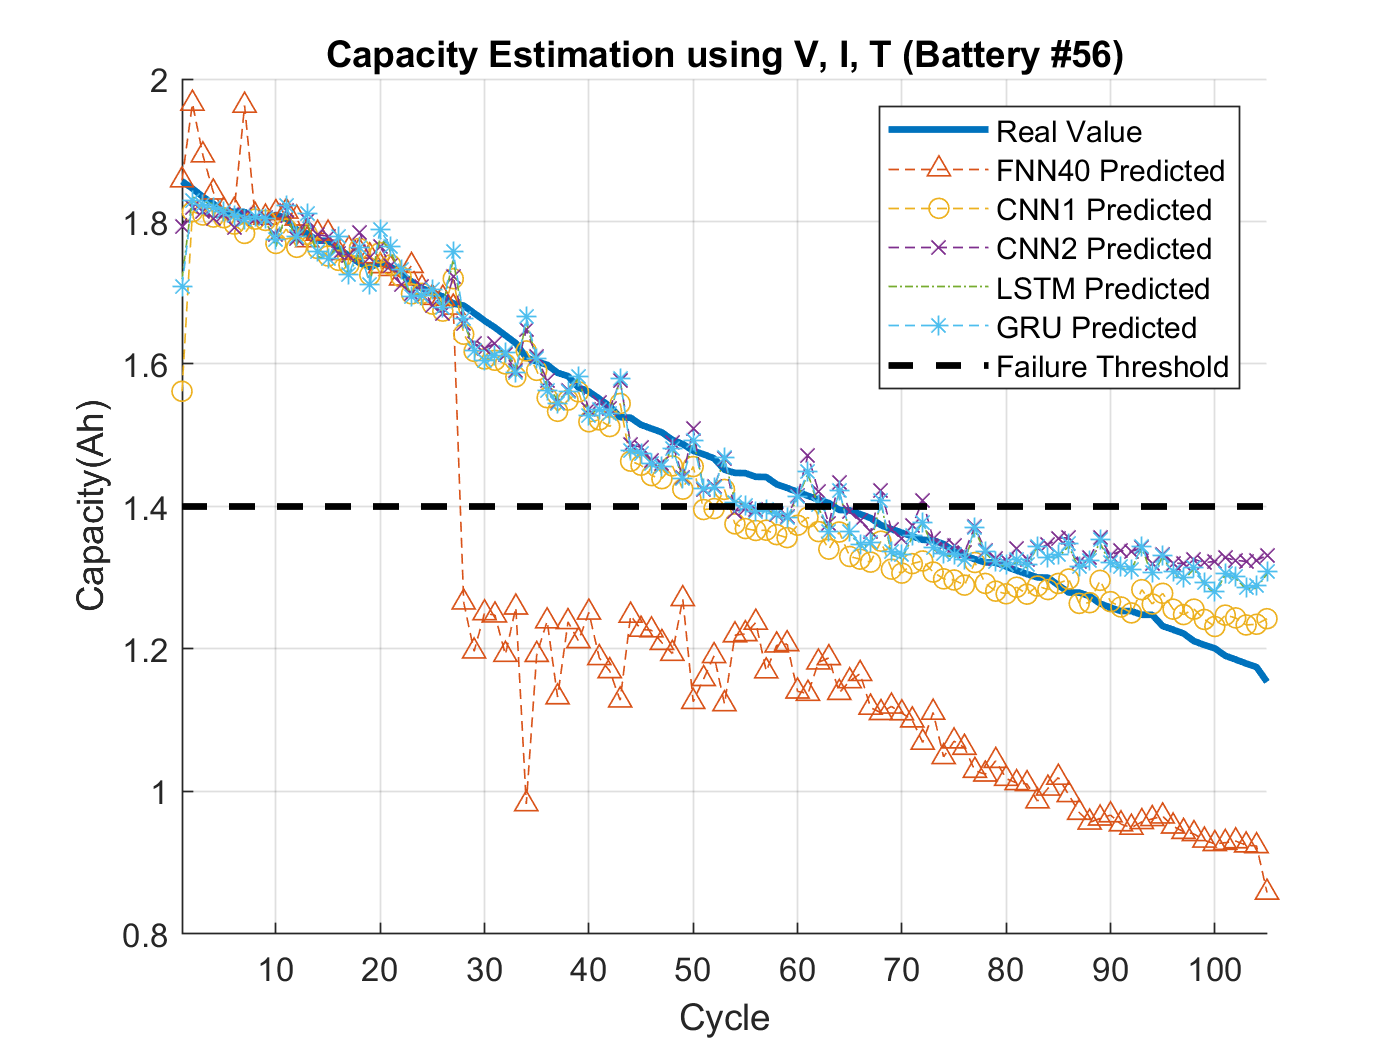

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;


layeGRU = [ ...
    sequenceInputLayer(inputSize)

rmse_pFNN40_0506 = 0.2669

    gruLayer(numHiddenUnits)

rmse_pCNN1_0506 = single
0.0500

    fullyConnectedLayer(1)

rmse_pCNN2_0506 = single
0.0547

    regressionLayer

rmse_pLSTM_0506 = single
0.0488

    ];

rmse_pGRU_0506 = single
0.0505

rmse_pFNN40_0506 = 0.2669

cellx = num2cell(Train_Input', 1)';

rmse_pCNN1_0506 = single
0.0500

cellyB = num2cell(Train_Output);

rmse_pCNN2_0506 = single
0.0547

rmse_pLSTM_0506 = single
0.0488

traincellx = cellx(tr.trainInd, :);

rmse_pGRU_0506 = single
0.0505

valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);

Unrecognized function or variable 'x_0'.

testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

%netGRU.trainParam.showWindow=0;
netGRU = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## Save model 

% https://kr.mathworks.com/matlabceloadntral/answers/264160-how-to-save-and-reuse-a-trained-neural-network

netFNN40_05_v2 = netFNN40;
netCNN1_05_v2 = netCNN1;
netCNN2_05_v2 = netCNN2;
netLSTM_05_v2 = netLSTM;
netGRU_05_v2 = netGRU;




### Prediciton using each 5 trained model

Make a prediction using trained models

pFNN40 = netFNN40(Train_Input(tr.testInd, :)');

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

cellx = num2cell(Train_Input(tr.testInd, :)', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_05plus06plus07_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end
pCNN1 = predict(netCNN1, x_4d);

- CNN2 : 2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

pCNN2 = predict(netCNN2, x_4d);

- LSTM : 1 lstm layer with 100 hidden units

pLSTM = cell2mat(predict(netLSTM, num2cell(Train_Input(tr.testInd, :)', 1)));

- GRU : 1 gru layer with 100 hidden units

pGRU = cell2mat(predict(netGRU, num2cell(Train_Input(tr.testInd, :)', 1)));

Denormalization for graphical ouput. Multiplying the range of original and add minimum value.

Train_Output = Train_Output(tr.testInd, :)*cap_all_rate + cap_all_min;
pFNN40 = pFNN40*cap_all_rate + cap_all_min;
pCNN1 = pCNN1*cap_all_rate + cap_all_min;
pCNN2 = pCNN2*cap_all_rate + cap_all_min;
pLSTM = pLSTM*cap_all_rate + cap_all_min;
pGRU = pGRU*cap_all_rate + cap_all_min;

### Result visualization

Visualize the prediction result. Battery capacity estimation based multi-channel charing profiles, using Voltage, Current and temperature.

total_cycle = length(Train_Output);
figure, hold on, grid on,
plot(Train_Output, 'linewidth', 2), plot(pFNN40, '^--'), plot(pCNN1, 'o--'), plot(pCNN2, 'x--'), plot(pLSTM, '-.'),plot(pGRU, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', '5+6+7', ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

RMSE

rmse_pFNN40 = sqrt(mean(( Train_Output' - pFNN40 ).^2))
rmse_pCNN1  = sqrt(mean(( Train_Output' - pCNN1' ).^2))
rmse_pCNN2  = sqrt(mean(( Train_Output' - pCNN2' ).^2))
rmse_pLSTM  = sqrt(mean(( Train_Output' - pLSTM' ).^2))
rmse_pGRU = sqrt(mean(( Train_Output' - pGRU' ).^2))

### Prediciton #56 by model #5. 


BatteryNum = 56;
pFNN40_0506 = netFNN40_05_v2(x_0506');
total_cycle = length(pFNN40_0506);
cellx = num2cell(x_0506', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0506 = predict(netCNN1_05_v2, x_4d);
pCNN2_0506 = predict(netCNN2_05_v2, x_4d);
pLSTM_0506 = cell2mat(predict(netLSTM_05_v2, num2cell(x_0506', 1)));
pGRU_0506 = cell2mat(predict(netGRU_05_v2, num2cell(x_0506', 1)));

y_0506 = yCap_0506 *cap_all_rate + cap_all_min ;
pFNN40_0506 = pFNN40_0506 *cap_all_rate + cap_all_min ;
pCNN1_0506 = pCNN1_0506 *cap_all_rate + cap_all_min ;
pCNN2_0506 = pCNN2_0506 *cap_all_rate + cap_all_min ;
pLSTM_0506 = pLSTM_0506 *cap_all_rate + cap_all_min ;
pGRU_0506 = pGRU_0506 *cap_all_rate + cap_all_min ;

figure, hold on, grid on,
plot(y_0506, 'linewidth', 2), plot(pFNN40_0506, '^--'), plot(pCNN1_0506, 'o--'), plot(pCNN2_0506, 'x--'), plot(pLSTM_0506, '-.'),plot(pGRU_0506, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')


rmse_pFNN40_0506 = sqrt(mean(( y_0506(1:length(pFNN40_0506)) - pFNN40_0506').^2))
rmse_pCNN1_0506  = sqrt(mean(( y_0506 - pCNN1_0506 ).^2))
rmse_pCNN2_0506  = sqrt(mean(( y_0506 - pCNN2_0506 ).^2))
rmse_pLSTM_0506  = sqrt(mean(( y_0506 - pLSTM_0506 ).^2))
rmse_pGRU_0506   = sqrt(mean(( y_0506 - pGRU_0506  ).^2))
rmse_pFNN40_0506
rmse_pCNN1_0506
rmse_pCNN2_0506
rmse_pLSTM_0506
rmse_pGRU_0506

# x = 06 y = cap 

BatteryNum = 6;
Train_Input = x_0;
Train_Output = yCap_06;

- FNN with 10 hidden neurons.

netFNN10 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN10.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN10, tr] = train(netFNN10, Train_Input', Train_Output', 'useparallel',  'yes');

- FNN with 40 hidden neurons.

netFNN40 = feedforwardnet(40);
netFNN40.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN40.divideParam.trainInd = tr.trainInd;
netFNN40.divideParam.valInd = tr.valInd;
netFNN40.divideParam.testInd = tr.testInd;
netFNN40.trainParam.epochs = 300;
netFNN40 = train(netFNN40, Train_Input', Train_Output', 'useparallel', 'yes');

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

layerCNN1 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], 10, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 5, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
cellx = num2cell(Train_Input', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(Train_Output);
tbl = table(cellx);
tbl.cellyB = cellyB;

Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', valtbl);

netCNN1 = trainNetwork(Traintbl, layerCNN1, options);

- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

layerCNN2 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], charVIT_05plus06plus07_input_size, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], round(charVIT_05plus06plus07_input_size / 2) , 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
netCNN2 = trainNetwork(Traintbl, layerCNN2, options);

- LSTM : 1 lstm layer with 50 hidden units

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layersLSTM = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

netLSTM = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## GRU

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layeGRU = [ ...
    sequenceInputLayer(inputSize)
    gruLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

%netGRU.trainParam.showWindow=0;
netGRU = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## Save model 

% https://kr.mathworks.com/matlabceloadntral/answers/264160-how-to-save-and-reuse-a-trained-neural-network

netFNN40_06_v2 = netFNN40;
netCNN1_06_v2 = netCNN1;
netCNN2_06_v2 = netCNN2;
netLSTM_06_v2 = netLSTM;
netGRU_06_v2 = netGRU;



### Prediciton using each 5 trained model

Make a prediction using trained models

pFNN40 = netFNN40(Train_Input(tr.testInd, :)');

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

cellx = num2cell(Train_Input(tr.testInd, :)', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_05plus06plus07_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end
pCNN1 = predict(netCNN1, x_4d);

- CNN2 : 2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

pCNN2 = predict(netCNN2, x_4d);

- LSTM : 1 lstm layer with 100 hidden units

pLSTM = cell2mat(predict(netLSTM, num2cell(Train_Input(tr.testInd, :)', 1)));

- GRU : 1 gru layer with 100 hidden units

pGRU = cell2mat(predict(netGRU, num2cell(Train_Input(tr.testInd, :)', 1)));

Denormalization for graphical ouput. Multiplying the range of original and add minimum value.

Train_Output = Train_Output(tr.testInd, :)*cap_all_rate + cap_all_min;
pFNN40 = pFNN40*cap_all_rate + cap_all_min;
pCNN1 = pCNN1*cap_all_rate + cap_all_min;
pCNN2 = pCNN2*cap_all_rate + cap_all_min;
pLSTM = pLSTM*cap_all_rate + cap_all_min;
pGRU = pGRU*cap_all_rate + cap_all_min;

### Result visualization

Visualize the prediction result. Battery capacity estimation based multi-channel charing profiles, using Voltage, Current and temperature.

total_cycle = length(Train_Output);
figure, hold on, grid on,
plot(Train_Output, 'linewidth', 2), plot(pFNN40, '^--'), plot(pCNN1, 'o--'), plot(pCNN2, 'x--'), plot(pLSTM, '-.'),plot(pGRU, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', '5+6+7', ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

RMSE

rmse_pFNN40 = sqrt(mean(( Train_Output' - pFNN40 ).^2))
rmse_pCNN1  = sqrt(mean(( Train_Output' - pCNN1' ).^2))
rmse_pCNN2  = sqrt(mean(( Train_Output' - pCNN2' ).^2))
rmse_pLSTM  = sqrt(mean(( Train_Output' - pLSTM' ).^2))
rmse_pGRU = sqrt(mean(( Train_Output' - pGRU' ).^2))

### Prediciton #56 by model #6. 


BatteryNum = 56;
pFNN40_0506 = netFNN40_06_v2(x_0506');
total_cycle = length(pFNN40_0506);
cellx = num2cell(x_0506', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0506 = predict(netCNN1_06_v2, x_4d);
pCNN2_0506 = predict(netCNN2_06_v2, x_4d);
pLSTM_0506 = cell2mat(predict(netLSTM_06_v2, num2cell(x_0506', 1)));
pGRU_0506 = cell2mat(predict(netGRU_06_v2, num2cell(x_0506', 1)));

y_0506 = yCap_0506 *cap_all_rate + cap_all_min ;
pFNN40_0506 = pFNN40_0506 *cap_all_rate + cap_all_min ;
pCNN1_0506 = pCNN1_0506 *cap_all_rate + cap_all_min ;
pCNN2_0506 = pCNN2_0506 *cap_all_rate + cap_all_min ;
pLSTM_0506 = pLSTM_0506 *cap_all_rate + cap_all_min ;
pGRU_0506 = pGRU_0506 *cap_all_rate + cap_all_min ;

figure, hold on, grid on,
plot(y_0506, 'linewidth', 2), plot(pFNN40_0506, '^--'), plot(pCNN1_0506, 'o--'), plot(pCNN2_0506, 'x--'), plot(pLSTM_0506, '-.'),plot(pGRU_0506, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')


rmse_pFNN40_0506 = sqrt(mean(( y_0506(1:length(pFNN40_0506)) - pFNN40_0506').^2))
rmse_pCNN1_0506  = sqrt(mean(( y_0506 - pCNN1_0506 ).^2))
rmse_pCNN2_0506  = sqrt(mean(( y_0506 - pCNN2_0506 ).^2))
rmse_pLSTM_0506  = sqrt(mean(( y_0506 - pLSTM_0506 ).^2))
rmse_pGRU_0506   = sqrt(mean(( y_0506 - pGRU_0506  ).^2))
rmse_pFNN40_0506
rmse_pCNN1_0506
rmse_pCNN2_0506
rmse_pLSTM_0506
rmse_pGRU_0506

# x = 07 y = cap 

BatteryNum = 7;
Train_Input = x_07;
Train_Output = yCap_07;

- FNN with 10 hidden neurons.

netFNN10 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN10.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN10, tr] = train(netFNN10, Train_Input', Train_Output', 'useparallel',  'yes');

- FNN with 40 hidden neurons.

netFNN40 = feedforwardnet(40);
netFNN40.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN40.divideParam.trainInd = tr.trainInd;
netFNN40.divideParam.valInd = tr.valInd;
netFNN40.divideParam.testInd = tr.testInd;
netFNN40.trainParam.epochs = 300;
netFNN40 = train(netFNN40, Train_Input', Train_Output', 'useparallel', 'yes');

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

layerCNN1 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], 10, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 5, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
cellx = num2cell(Train_Input', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(Train_Output);
tbl = table(cellx);
tbl.cellyB = cellyB;

Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', valtbl);

netCNN1 = trainNetwork(Traintbl, layerCNN1, options);

- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

layerCNN2 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], charVIT_05plus06plus07_input_size, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], round(charVIT_05plus06plus07_input_size / 2) , 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
netCNN2 = trainNetwork(Traintbl, layerCNN2, options);

- LSTM : 1 lstm layer with 50 hidden units

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layersLSTM = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

netLSTM = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## GRU

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layeGRU = [ ...
    sequenceInputLayer(inputSize)
    gruLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

%netGRU.trainParam.showWindow=0;
netGRU = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## Save model 

% https://kr.mathworks.com/matlabceloadntral/answers/264160-how-to-save-and-reuse-a-trained-neural-network

netFNN40_07_v2 = netFNN40;
netCNN1_07_v2 = netCNN1;
netCNN2_07_v2 = netCNN2;
netLSTM_07_v2 = netLSTM;
netGRU_07_v2 = netGRU;




### Prediciton using each 5 trained model

Make a prediction using trained models

pFNN40 = netFNN40(Train_Input(tr.testInd, :)');

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

cellx = num2cell(Train_Input(tr.testInd, :)', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_05plus06plus07_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end
pCNN1 = predict(netCNN1, x_4d);

- CNN2 : 2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

pCNN2 = predict(netCNN2, x_4d);

- LSTM : 1 lstm layer with 100 hidden units

pLSTM = cell2mat(predict(netLSTM, num2cell(Train_Input(tr.testInd, :)', 1)));

- GRU : 1 gru layer with 100 hidden units

pGRU = cell2mat(predict(netGRU, num2cell(Train_Input(tr.testInd, :)', 1)));

Denormalization for graphical ouput. Multiplying the range of original and add minimum value.

Train_Output = Train_Output(tr.testInd, :)*cap_all_rate + cap_all_min;
pFNN40 = pFNN40*cap_all_rate + cap_all_min;
pCNN1 = pCNN1*cap_all_rate + cap_all_min;
pCNN2 = pCNN2*cap_all_rate + cap_all_min;
pLSTM = pLSTM*cap_all_rate + cap_all_min;
pGRU = pGRU*cap_all_rate + cap_all_min;

### Result visualization

Visualize the prediction result. Battery capacity estimation based multi-channel charing profiles, using Voltage, Current and temperature.

total_cycle = length(Train_Output);
figure, hold on, grid on,
plot(Train_Output, 'linewidth', 2), plot(pFNN40, '^--'), plot(pCNN1, 'o--'), plot(pCNN2, 'x--'), plot(pLSTM, '-.'),plot(pGRU, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', '5+6+7', ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

RMSE

rmse_pFNN40 = sqrt(mean(( Train_Output' - pFNN40 ).^2))
rmse_pCNN1  = sqrt(mean(( Train_Output' - pCNN1' ).^2))
rmse_pCNN2  = sqrt(mean(( Train_Output' - pCNN2' ).^2))
rmse_pLSTM  = sqrt(mean(( Train_Output' - pLSTM' ).^2))
rmse_pGRU = sqrt(mean(( Train_Output' - pGRU' ).^2))

### Prediciton #56 by model #7. 


BatteryNum = 56;
pFNN40_0506 = netFNN40_07_v2(x_0506');
total_cycle = length(pFNN40_0506);
cellx = num2cell(x_0506', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0506 = predict(netCNN1_07_v2, x_4d);
pCNN2_0506 = predict(netCNN2_07_v2, x_4d);
pLSTM_0506 = cell2mat(predict(netLSTM_07_v2, num2cell(x_0506', 1)));
pGRU_0506 = cell2mat(predict(netGRU_07_v2, num2cell(x_0506', 1)));

y_0506 = yCap_0506 *cap_all_rate + cap_all_min ;
pFNN40_0506 = pFNN40_0506 *cap_all_rate + cap_all_min ;
pCNN1_0506 = pCNN1_0506 *cap_all_rate + cap_all_min ;
pCNN2_0506 = pCNN2_0506 *cap_all_rate + cap_all_min ;
pLSTM_0506 = pLSTM_0506 *cap_all_rate + cap_all_min ;
pGRU_0506 = pGRU_0506 *cap_all_rate + cap_all_min ;

figure, hold on, grid on,
plot(y_0506, 'linewidth', 2), plot(pFNN40_0506, '^--'), plot(pCNN1_0506, 'o--'), plot(pCNN2_0506, 'x--'), plot(pLSTM_0506, '-.'),plot(pGRU_0506, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')


rmse_pFNN40_0506 = sqrt(mean(( y_0506(1:length(pFNN40_0506)) - pFNN40_0506').^2))
rmse_pCNN1_0506  = sqrt(mean(( y_0506 - pCNN1_0506 ).^2))
rmse_pCNN2_0506  = sqrt(mean(( y_0506 - pCNN2_0506 ).^2))
rmse_pLSTM_0506  = sqrt(mean(( y_0506 - pLSTM_0506 ).^2))
rmse_pGRU_0506   = sqrt(mean(( y_0506 - pGRU_0506  ).^2))
rmse_pFNN40_0506
rmse_pCNN1_0506
rmse_pCNN2_0506
rmse_pLSTM_0506
rmse_pGRU_0506

# x = 0506 y = cap 

BatteryNum = 563;
Train_Input = x_0506;
Train_Output = yCap_0506;

- FNN with 10 hidden neurons.

netFNN10 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN10.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN10, tr] = train(netFNN10, Train_Input', Train_Output', 'useparallel',  'yes');

- FNN with 40 hidden neurons.

netFNN40 = feedforwardnet(40);
netFNN40.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN40.divideParam.trainInd = tr.trainInd;
netFNN40.divideParam.valInd = tr.valInd;
netFNN40.divideParam.testInd = tr.testInd;
netFNN40.trainParam.epochs = 300;
netFNN40 = train(netFNN40, Train_Input', Train_Output', 'useparallel', 'yes');

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

layerCNN1 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], 10, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 5, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
cellx = num2cell(Train_Input', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(Train_Output);
tbl = table(cellx);
tbl.cellyB = cellyB;

Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', valtbl);

netCNN1 = trainNetwork(Traintbl, layerCNN1, options);

- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

layerCNN2 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], charVIT_05plus06plus07_input_size, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], round(charVIT_05plus06plus07_input_size / 2) , 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
netCNN2 = trainNetwork(Traintbl, layerCNN2, options);

- LSTM : 1 lstm layer with 50 hidden units

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layersLSTM = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

netLSTM = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## GRU

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layeGRU = [ ...
    sequenceInputLayer(inputSize)
    gruLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

%netGRU.trainParam.showWindow=0;
netGRU = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## Save model 

% https://kr.mathworks.com/matlabceloadntral/answers/264160-how-to-save-and-reuse-a-trained-neural-network

netFNN40_0506_v2 = netFNN40;
netCNN1_0506_v2 = netCNN1;
netCNN2_0506_v2 = netCNN2;
netLSTM_0506_v2 = netLSTM;
netGRU_0506_v2 = netGRU;



### Prediciton using each 5 trained model

Make a prediction using trained models

pFNN40 = netFNN40(Train_Input(tr.testInd, :)');

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

cellx = num2cell(Train_Input(tr.testInd, :)', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_05plus06plus07_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end
pCNN1 = predict(netCNN1, x_4d);

- CNN2 : 2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

pCNN2 = predict(netCNN2, x_4d);

- LSTM : 1 lstm layer with 100 hidden units

pLSTM = cell2mat(predict(netLSTM, num2cell(Train_Input(tr.testInd, :)', 1)));

- GRU : 1 gru layer with 100 hidden units

pGRU = cell2mat(predict(netGRU, num2cell(Train_Input(tr.testInd, :)', 1)));

Denormalization for graphical ouput. Multiplying the range of original and add minimum value.

Train_Output = Train_Output(tr.testInd, :)*cap_all_rate + cap_all_min;
pFNN40 = pFNN40*cap_all_rate + cap_all_min;
pCNN1 = pCNN1*cap_all_rate + cap_all_min;
pCNN2 = pCNN2*cap_all_rate + cap_all_min;
pLSTM = pLSTM*cap_all_rate + cap_all_min;
pGRU = pGRU*cap_all_rate + cap_all_min;

### Result visualization

Visualize the prediction result. Battery capacity estimation based multi-channel charing profiles, using Voltage, Current and temperature.

total_cycle = length(Train_Output);
figure, hold on, grid on,
plot(Train_Output, 'linewidth', 2), plot(pFNN40, '^--'), plot(pCNN1, 'o--'), plot(pCNN2, 'x--'), plot(pLSTM, '-.'),plot(pGRU, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', '5+6+7', ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

RMSE

rmse_pFNN40 = sqrt(mean(( Train_Output' - pFNN40 ).^2))
rmse_pCNN1  = sqrt(mean(( Train_Output' - pCNN1' ).^2))
rmse_pCNN2  = sqrt(mean(( Train_Output' - pCNN2' ).^2))
rmse_pLSTM  = sqrt(mean(( Train_Output' - pLSTM' ).^2))
rmse_pGRU = sqrt(mean(( Train_Output' - pGRU' ).^2))

### Prediciton #56 by model #56. 


BatteryNum = 56;
pFNN40_0506 = netFNN40_0506_v2(x_0506');
total_cycle = length(pFNN40_0506);
cellx = num2cell(x_0506', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0506 = predict(netCNN1_0506_v2, x_4d);
pCNN2_0506 = predict(netCNN2_0506_v2, x_4d);
pLSTM_0506 = cell2mat(predict(netLSTM_0506_v2, num2cell(x_0506', 1)));
pGRU_0506 = cell2mat(predict(netGRU_0506_v2, num2cell(x_0506', 1)));

y_0506 = yCap_0506 *cap_all_rate + cap_all_min ;
pFNN40_0506 = pFNN40_0506 *cap_all_rate + cap_all_min ;
pCNN1_0506 = pCNN1_0506 *cap_all_rate + cap_all_min ;
pCNN2_0506 = pCNN2_0506 *cap_all_rate + cap_all_min ;
pLSTM_0506 = pLSTM_0506 *cap_all_rate + cap_all_min ;
pGRU_0506 = pGRU_0506 *cap_all_rate + cap_all_min ;

figure, hold on, grid on,
plot(y_0506, 'linewidth', 2), plot(pFNN40_0506, '^--'), plot(pCNN1_0506, 'o--'), plot(pCNN2_0506, 'x--'), plot(pLSTM_0506, '-.'),plot(pGRU_0506, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')


rmse_pFNN40_0506 = sqrt(mean(( y_0506(1:length(pFNN40_0506)) - pFNN40_0506').^2))
rmse_pCNN1_0506  = sqrt(mean(( y_0506 - pCNN1_0506 ).^2))
rmse_pCNN2_0506  = sqrt(mean(( y_0506 - pCNN2_0506 ).^2))
rmse_pLSTM_0506  = sqrt(mean(( y_0506 - pLSTM_0506 ).^2))
rmse_pGRU_0506   = sqrt(mean(( y_0506 - pGRU_0506  ).^2))
rmse_pFNN40_0506
rmse_pCNN1_0506
rmse_pCNN2_0506
rmse_pLSTM_0506
rmse_pGRU_0506

# x = 0605 y = cap 

BatteryNum = 652;
Train_Input = x_0605;
Train_Output = yCap_0605;

- FNN with 10 hidden neurons.

netFNN10 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN10.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN10, tr] = train(netFNN10, Train_Input', Train_Output', 'useparallel',  'yes');

- FNN with 40 hidden neurons.

netFNN40 = feedforwardnet(40);
netFNN40.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN40.divideParam.trainInd = tr.trainInd;
netFNN40.divideParam.valInd = tr.valInd;
netFNN40.divideParam.testInd = tr.testInd;
netFNN40.trainParam.epochs = 300;
netFNN40 = train(netFNN40, Train_Input', Train_Output', 'useparallel', 'yes');

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

layerCNN1 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], 10, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 5, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
cellx = num2cell(Train_Input', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(Train_Output);
tbl = table(cellx);
tbl.cellyB = cellyB;

Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', valtbl);

netCNN1 = trainNetwork(Traintbl, layerCNN1, options);

- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

layerCNN2 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], charVIT_05plus06plus07_input_size, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], round(charVIT_05plus06plus07_input_size / 2) , 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
netCNN2 = trainNetwork(Traintbl, layerCNN2, options);

- LSTM : 1 lstm layer with 50 hidden units

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layersLSTM = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

netLSTM = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## GRU

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layeGRU = [ ...
    sequenceInputLayer(inputSize)
    gruLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

%netGRU.trainParam.showWindow=0;
netGRU = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## Save model 

% https://kr.mathworks.com/matlabceloadntral/answers/264160-how-to-save-and-reuse-a-trained-neural-network

netFNN40_0605_v2 = netFNN40;
netCNN1_0605_v2 = netCNN1;
netCNN2_0605_v2 = netCNN2;
netLSTM_0605_v2 = netLSTM;
netGRU_0605_v2 = netGRU;




### Prediciton using each 5 trained model

Make a prediction using trained models

pFNN40 = netFNN40(Train_Input(tr.testInd, :)');

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

cellx = num2cell(Train_Input(tr.testInd, :)', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_05plus06plus07_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end
pCNN1 = predict(netCNN1, x_4d);

- CNN2 : 2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

pCNN2 = predict(netCNN2, x_4d);

- LSTM : 1 lstm layer with 100 hidden units

pLSTM = cell2mat(predict(netLSTM, num2cell(Train_Input(tr.testInd, :)', 1)));

- GRU : 1 gru layer with 100 hidden units

pGRU = cell2mat(predict(netGRU, num2cell(Train_Input(tr.testInd, :)', 1)));

Denormalization for graphical ouput. Multiplying the range of original and add minimum value.

Train_Output = Train_Output(tr.testInd, :)*cap_all_rate + cap_all_min;
pFNN40 = pFNN40*cap_all_rate + cap_all_min;
pCNN1 = pCNN1*cap_all_rate + cap_all_min;
pCNN2 = pCNN2*cap_all_rate + cap_all_min;
pLSTM = pLSTM*cap_all_rate + cap_all_min;
pGRU = pGRU*cap_all_rate + cap_all_min;

### Result visualization

Visualize the prediction result. Battery capacity estimation based multi-channel charing profiles, using Voltage, Current and temperature.

total_cycle = length(Train_Output);
figure, hold on, grid on,
plot(Train_Output, 'linewidth', 2), plot(pFNN40, '^--'), plot(pCNN1, 'o--'), plot(pCNN2, 'x--'), plot(pLSTM, '-.'),plot(pGRU, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', '5+6+7', ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

RMSE

rmse_pFNN40 = sqrt(mean(( Train_Output' - pFNN40 ).^2))
rmse_pCNN1  = sqrt(mean(( Train_Output' - pCNN1' ).^2))
rmse_pCNN2  = sqrt(mean(( Train_Output' - pCNN2' ).^2))
rmse_pLSTM  = sqrt(mean(( Train_Output' - pLSTM' ).^2))
rmse_pGRU = sqrt(mean(( Train_Output' - pGRU' ).^2))

### Prediciton #56 by model #65. 


BatteryNum = 56;
pFNN40_0506 = netFNN40_0605_v2(x_0506');
total_cycle = length(pFNN40_0506);
cellx = num2cell(x_0506', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0506 = predict(netCNN1_0605_v2, x_4d);
pCNN2_0506 = predict(netCNN2_0605_v2, x_4d);
pLSTM_0506 = cell2mat(predict(netLSTM_0605_v2, num2cell(x_0506', 1)));
pGRU_0506 = cell2mat(predict(netGRU_0605_v2, num2cell(x_0506', 1)));

y_0506 = yCap_0506 *cap_all_rate + cap_all_min ;
pFNN40_0506 = pFNN40_0506 *cap_all_rate + cap_all_min ;
pCNN1_0506 = pCNN1_0506 *cap_all_rate + cap_all_min ;
pCNN2_0506 = pCNN2_0506 *cap_all_rate + cap_all_min ;
pLSTM_0506 = pLSTM_0506 *cap_all_rate + cap_all_min ;
pGRU_0506 = pGRU_0506 *cap_all_rate + cap_all_min ;

figure, hold on, grid on,
plot(y_0506, 'linewidth', 2), plot(pFNN40_0506, '^--'), plot(pCNN1_0506, 'o--'), plot(pCNN2_0506, 'x--'), plot(pLSTM_0506, '-.'),plot(pGRU_0506, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')


rmse_pFNN40_0506 = sqrt(mean(( y_0506(1:length(pFNN40_0506)) - pFNN40_0506').^2))
rmse_pCNN1_0506  = sqrt(mean(( y_0506 - pCNN1_0506 ).^2))
rmse_pCNN2_0506  = sqrt(mean(( y_0506 - pCNN2_0506 ).^2))
rmse_pLSTM_0506  = sqrt(mean(( y_0506 - pLSTM_0506 ).^2))
rmse_pGRU_0506   = sqrt(mean(( y_0506 - pGRU_0506  ).^2))
rmse_pFNN40_0506
rmse_pCNN1_0506
rmse_pCNN2_0506
rmse_pLSTM_0506
rmse_pGRU_0506

# x = 05plus06plus07 y = cap 

BatteryNum = 562;
Train_Input = x_05plus06;
Train_Output = yCap_05plus06;

- FNN with 10 hidden neurons.

netFNN10 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN10.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN10, tr] = train(netFNN10, Train_Input', Train_Output', 'useparallel',  'yes');

- FNN with 40 hidden neurons.

netFNN40 = feedforwardnet(40);
netFNN40.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN40.divideParam.trainInd = tr.trainInd;
netFNN40.divideParam.valInd = tr.valInd;
netFNN40.divideParam.testInd = tr.testInd;
netFNN40.trainParam.epochs = 300;
netFNN40 = train(netFNN40, Train_Input', Train_Output', 'useparallel', 'yes');

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

layerCNN1 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], 10, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 5, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
cellx = num2cell(Train_Input', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(Train_Output);
tbl = table(cellx);
tbl.cellyB = cellyB;

Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', valtbl);

netCNN1 = trainNetwork(Traintbl, layerCNN1, options);

- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

layerCNN2 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], charVIT_05plus06plus07_input_size, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], round(charVIT_05plus06plus07_input_size / 2) , 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
netCNN2 = trainNetwork(Traintbl, layerCNN2, options);

- LSTM : 1 lstm layer with 50 hidden units

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layersLSTM = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

netLSTM = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## GRU

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layeGRU = [ ...
    sequenceInputLayer(inputSize)
    gruLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

%netGRU.trainParam.showWindow=0;
netGRU = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## Save model 

% https://kr.mathworks.com/matlabceloadntral/answers/264160-how-to-save-and-reuse-a-trained-neural-network

netFNN40_05plus06_v2 = netFNN40;
netCNN1_05plus06_v2 = netCNN1;
netCNN2_05plus06_v2 = netCNN2;
netLSTM_05plus06_v2 = netLSTM;
netGRU_05plus06_v2 = netGRU;




### Prediciton using each 5 trained model

Make a prediction using trained models

pFNN40 = netFNN40(Train_Input(tr.testInd, :)');

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

cellx = num2cell(Train_Input(tr.testInd, :)', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_05plus06plus07_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end
pCNN1 = predict(netCNN1, x_4d);

- CNN2 : 2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

pCNN2 = predict(netCNN2, x_4d);

- LSTM : 1 lstm layer with 100 hidden units

pLSTM = cell2mat(predict(netLSTM, num2cell(Train_Input(tr.testInd, :)', 1)));

- GRU : 1 gru layer with 100 hidden units

pGRU = cell2mat(predict(netGRU, num2cell(Train_Input(tr.testInd, :)', 1)));

Denormalization for graphical ouput. Multiplying the range of original and add minimum value.

Train_Output = Train_Output(tr.testInd, :)*cap_all_rate + cap_all_min;
pFNN40 = pFNN40*cap_all_rate + cap_all_min;
pCNN1 = pCNN1*cap_all_rate + cap_all_min;
pCNN2 = pCNN2*cap_all_rate + cap_all_min;
pLSTM = pLSTM*cap_all_rate + cap_all_min;
pGRU = pGRU*cap_all_rate + cap_all_min;

### Result visualization

Visualize the prediction result. Battery capacity estimation based multi-channel charing profiles, using Voltage, Current and temperature.

total_cycle = length(Train_Output);
figure, hold on, grid on,
plot(Train_Output, 'linewidth', 2), plot(pFNN40, '^--'), plot(pCNN1, 'o--'), plot(pCNN2, 'x--'), plot(pLSTM, '-.'),plot(pGRU, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', '5+6+7', ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

RMSE

rmse_pFNN40 = sqrt(mean(( Train_Output' - pFNN40 ).^2))
rmse_pCNN1  = sqrt(mean(( Train_Output' - pCNN1' ).^2))
rmse_pCNN2  = sqrt(mean(( Train_Output' - pCNN2' ).^2))
rmse_pLSTM  = sqrt(mean(( Train_Output' - pLSTM' ).^2))
rmse_pGRU = sqrt(mean(( Train_Output' - pGRU' ).^2))

### Prediciton #56 by model #5+#6  


BatteryNum = 56;
pFNN40_0506 = netFNN40_05plus06_v2(x_0506');
total_cycle = length(pFNN40_0506);
cellx = num2cell(x_0506', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0506 = predict(netCNN1_05plus06_v2, x_4d);
pCNN2_0506 = predict(netCNN2_05plus06_v2, x_4d);
pLSTM_0506 = cell2mat(predict(netLSTM_05plus06_v2, num2cell(x_0506', 1)));
pGRU_0506 = cell2mat(predict(netGRU_05plus06_v2, num2cell(x_0506', 1)));

y_0506 = yCap_0506 *cap_all_rate + cap_all_min ;
pFNN40_0506 = pFNN40_0506 *cap_all_rate + cap_all_min ;
pCNN1_0506 = pCNN1_0506 *cap_all_rate + cap_all_min ;
pCNN2_0506 = pCNN2_0506 *cap_all_rate + cap_all_min ;
pLSTM_0506 = pLSTM_0506 *cap_all_rate + cap_all_min ;
pGRU_0506 = pGRU_0506 *cap_all_rate + cap_all_min ;

figure, hold on, grid on,
plot(y_0506, 'linewidth', 2), plot(pFNN40_0506, '^--'), plot(pCNN1_0506, 'o--'), plot(pCNN2_0506, 'x--'), plot(pLSTM_0506, '-.'),plot(pGRU_0506, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')


rmse_pFNN40_0506 = sqrt(mean(( y_0506(1:length(pFNN40_0506)) - pFNN40_0506').^2))
rmse_pCNN1_0506  = sqrt(mean(( y_0506 - pCNN1_0506 ).^2))
rmse_pCNN2_0506  = sqrt(mean(( y_0506 - pCNN2_0506 ).^2))
rmse_pLSTM_0506  = sqrt(mean(( y_0506 - pLSTM_0506 ).^2))
rmse_pGRU_0506   = sqrt(mean(( y_0506 - pGRU_0506  ).^2))
rmse_pFNN40_0506
rmse_pCNN1_0506
rmse_pCNN2_0506
rmse_pLSTM_0506
rmse_pGRU_0506

# x = ???? y = cap 

BatteryNum = 5673;
Train_Input = x_05plus06plus07;
Train_Output = yCap_05plus06plus07;